# Design of a Controller for an Unstable System with Three Poles

## Description of the Feedback Control System

Consider the feedback control system described by the block-scheme shown in the following figure   

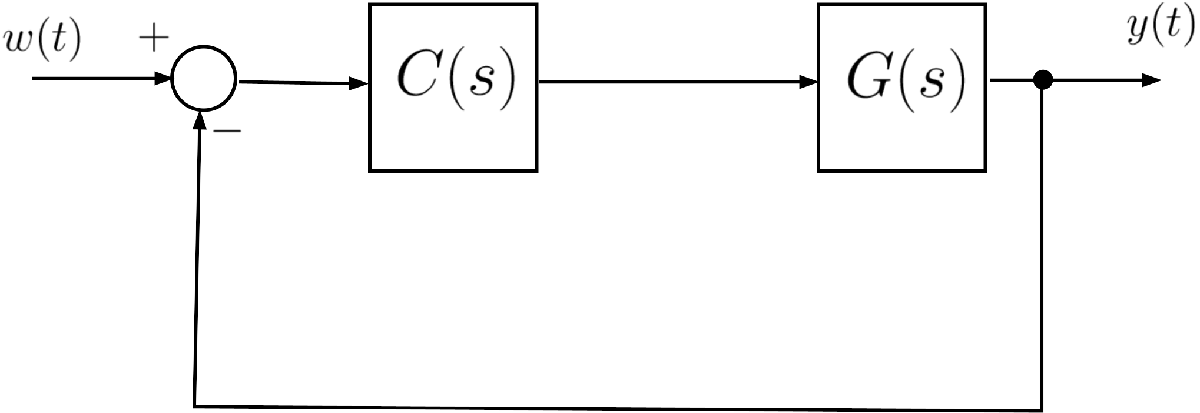	

where $G(s)$ is given by                


$$G(s) = \frac{4}{(1-s)\,(1+10\,s)\,(1+2\,s)}$$


## **Question**		

**Q1**: Design a controller $C(s)$ such that all following requirements are simultaneously met: 

- The crossover angular frequency satisfies $\omega_c \ge 4\;\text{rad/s}$; 

- The phase margin satisfies $\varphi_m \ge 45^{\degree}$.

## Foreword to the Provided Solution

The proposed problem admits to more than one possible solution. The proposed solution is not the only admissible solution (in fact, the problem admits to infinite solutions), nor is it optimal. It is only a simple solution that can be obtained using the tools available in MATLAB's Control System Toolbox.

You are encouraged to solve the problem by finding alternative solutions and comparing the performance of the control system using your solution with those obtained using the proposed solution in this live script.  				

## Solution 

Since the system is open-loop unstable, the Bode stability criterion cannot be used in the way that is usual for the loop-shaping approach to the design of the controller for minimum-phase systems. Hence, as suggested in Example 3 in slides 41-44 of Part 10 of the lecture handouts, we use a **dual-loop control scheme**, as shown in the Figure below 

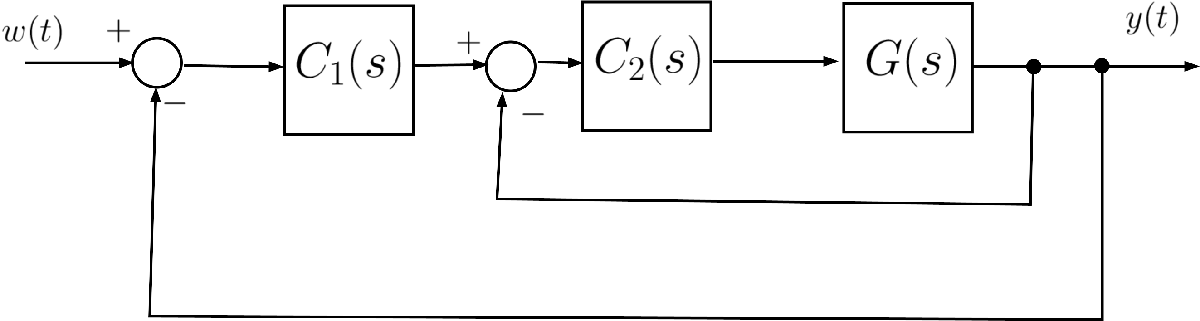

The design of the controller $C(s)$ is carried out by the following logical steps:

- The controller $C_2(s)$ is designed so as the **inner-loop transfer function **$F_2(s)$ from the output of the block $C_1(s)$ is **asymptotically** **stable**.

-  Subsequently, $C_1(s)$ will be designed to meet the other requirements.

## A1: Answer to Question Q1

### Design of the Inner Loop Controller

Let's consider


$$C_2(s) = \mu_2\;, \quad \mu_2 \in \mathbb{R}$$


Using the controller $C_2(s)$ only, are we able to stabilise the system $G(s)$, i.e., to guarantee the asymptotic stability for the closed-loop system $F_2(s) = \frac{C_2(s)\,G(s)}{1+C_2(s)\,G(s)}$?

Let's write the open-loop transfer function $L_2(s)$, according to the standard notation used to analyse the root loci


$$L_2(s) = C_2(s)\,G(s) = \frac{4\, \mu_2}{(1-s)\,(1+10\,s)\,(1+2\,s)} \;\Longrightarrow\; L_2(s) = -\frac{\mu_2}{5} \frac{1}{(s-1)\,\left(s+\frac{1}{10}\right)\,\left(s+\frac{1}{2}\right)} \;
\Longrightarrow \;
L_2(s) = \varrho\, \frac{1}{(s-1)\,\left(s+\frac{1}{10}\right)\,\left(s+\frac{1}{2}\right)}$$


with $\varrho = -\frac{\mu_2}{5}$. Thus, $\mu_2 >0 \;\Longrightarrow \; \varrho <0$. It means when $\mu_2>0$, we are analysing the Inverse Root Locus for $L_2(s)$, whereas when $\mu_2<0$ we are considering the Direct Root Locus of $L_2(s)$.

#### **Preliminar Analysis**

Let's define the transfer function of the process $G(s)$ and configure the MATLAB Search Path, by adding the folder containing the M-code able to compute and plot the asymptotic approximation of the Bode diagrams of the frequency response of a given transfer function.

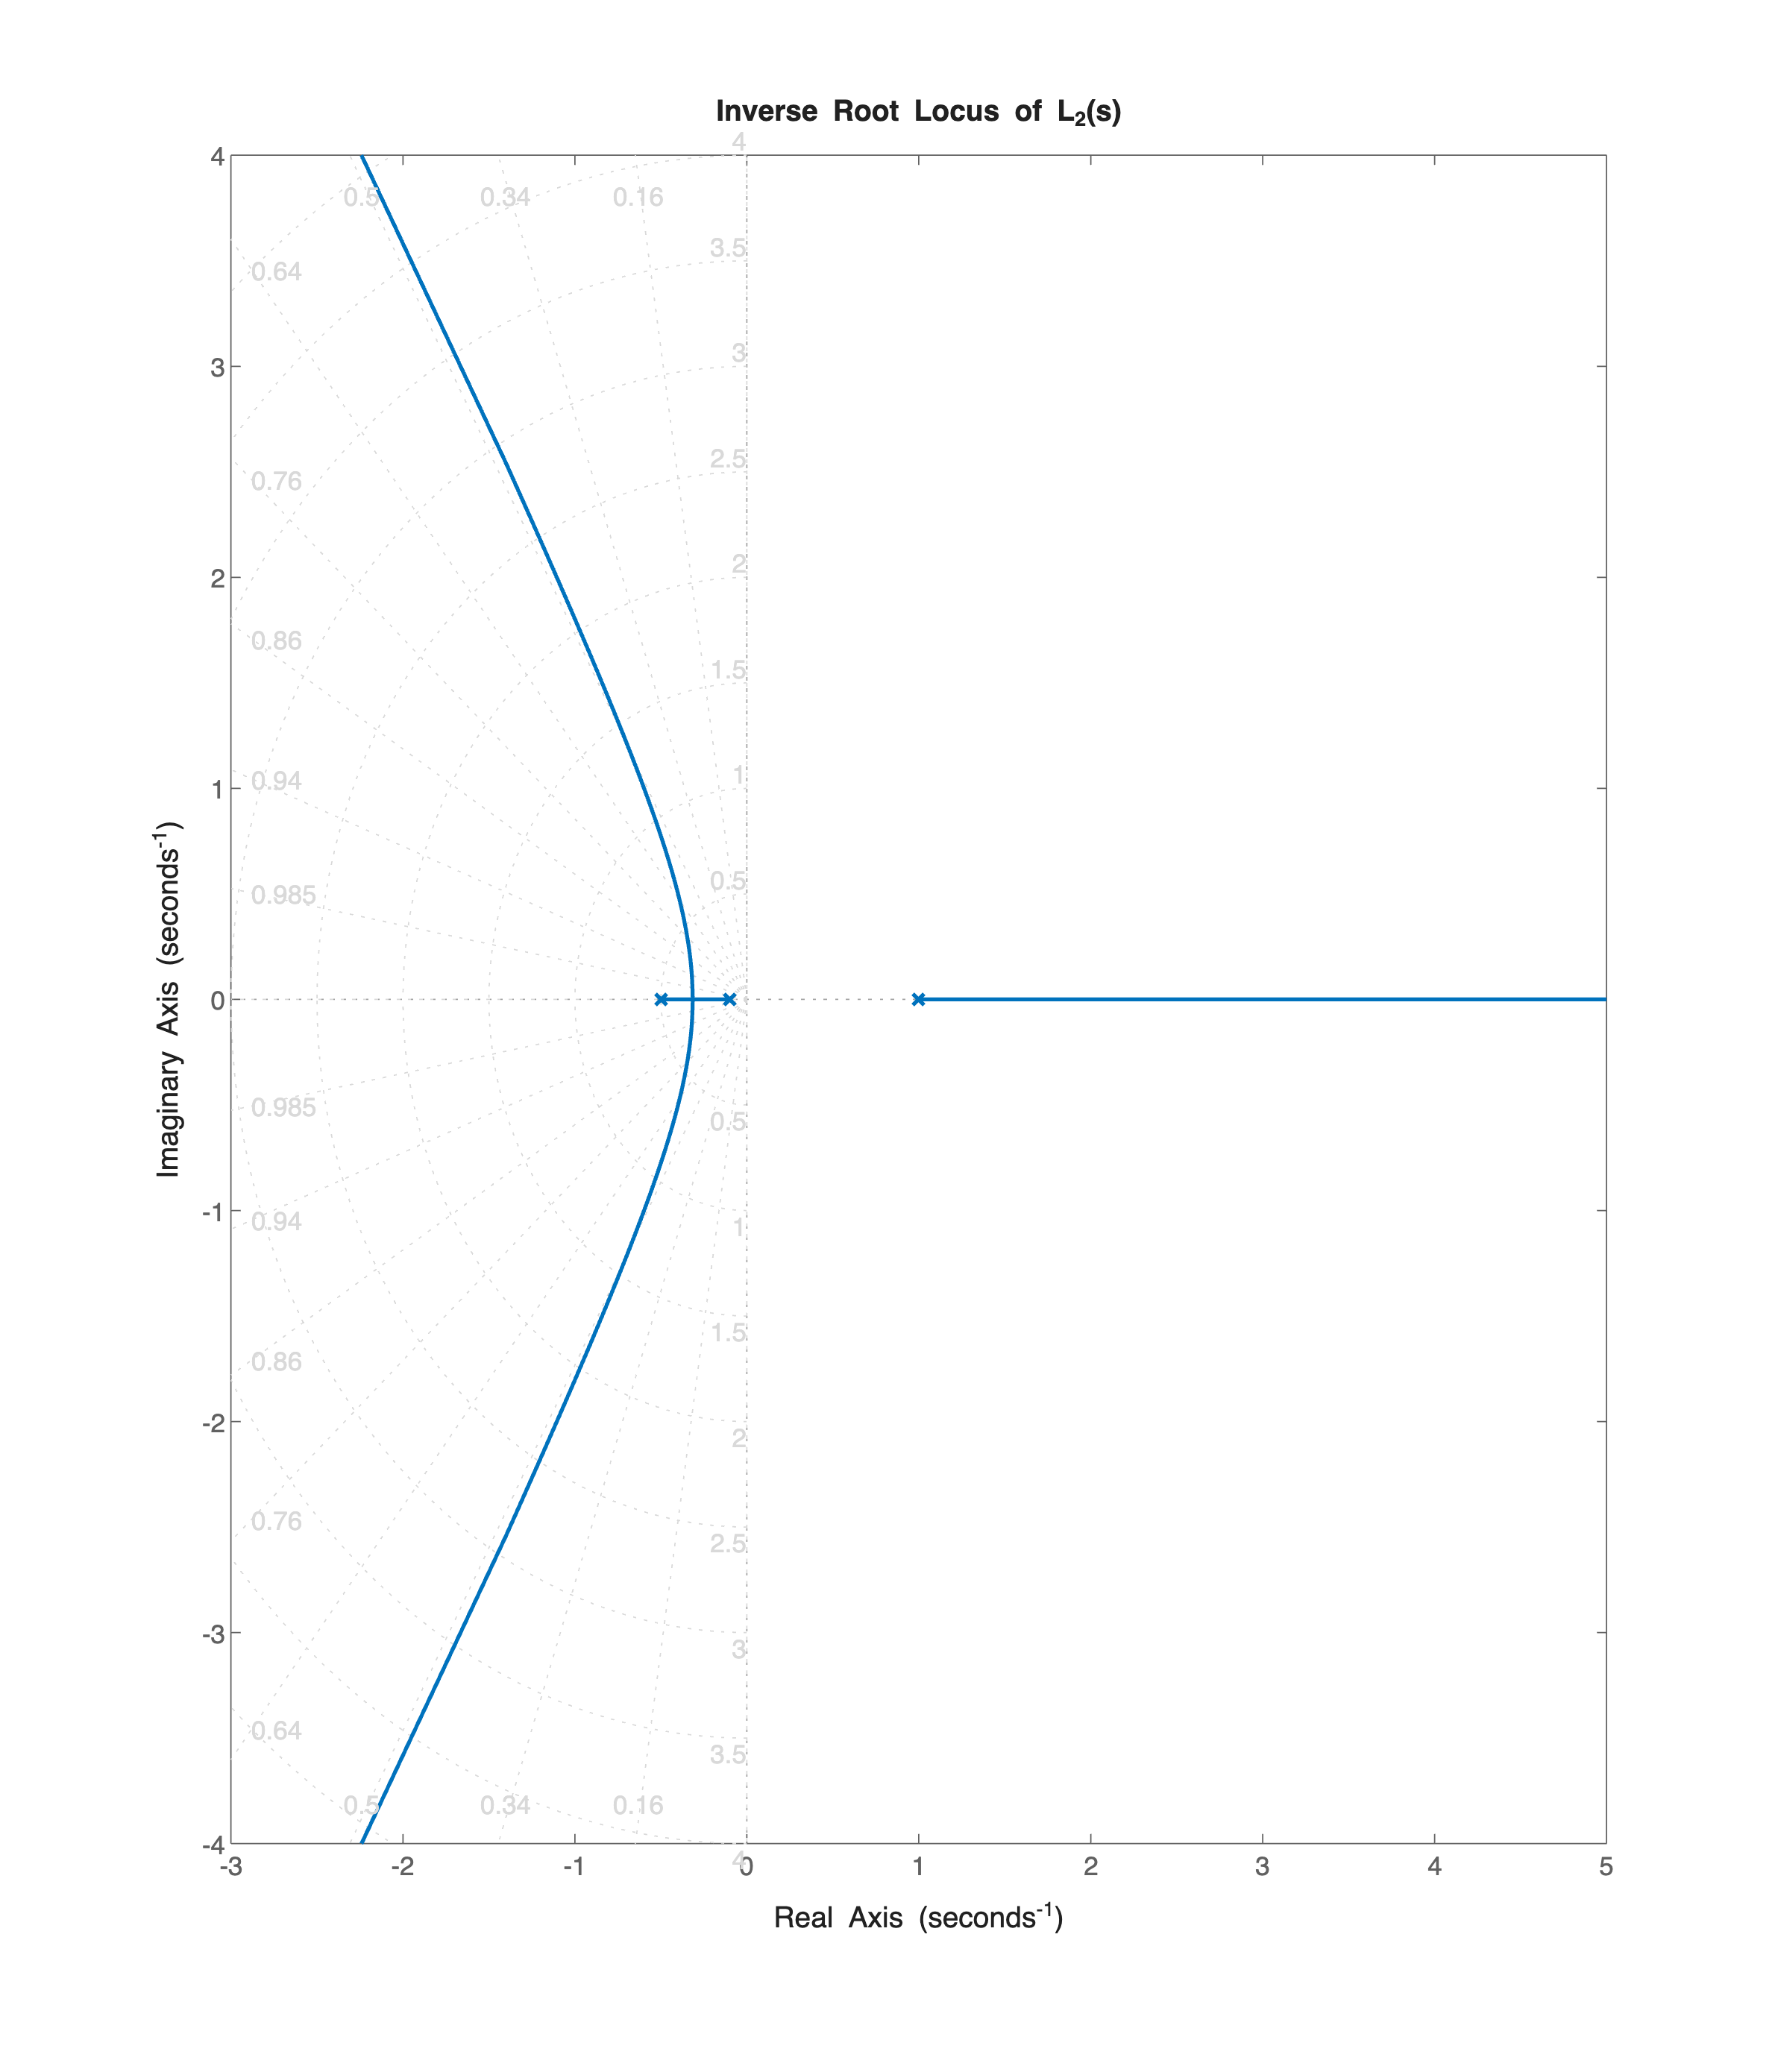

clear

% adding folders (and subfolders) to search path
addpath(genpath('BodeDiagram/'))

% let's define the transfer function builder element
s=tf('s');

Gs = 4/((1-s)*(1+10*s)*(1+2*s)); % the unstable process G(s)

hf0 = figure('Units','centimeters','Position',[0.01, 0.01, 24, 28]);
rlpH = rlocusplot(hf0, Gs);
title("Inverse Root Locus of L_2(s)");
rlpH.Responses(1).LineWidth = 1.5;
sgrid

As you can deduce analysing the figure, a pure gain controller $C_2(s) = \mu_2$, with $\mu_2>0$, cannot stabilise in closed-loop the system $G(s)$: there is always a real positive closed-loop pole.

What about using a negative gain for the controller $C_2(s)$? 

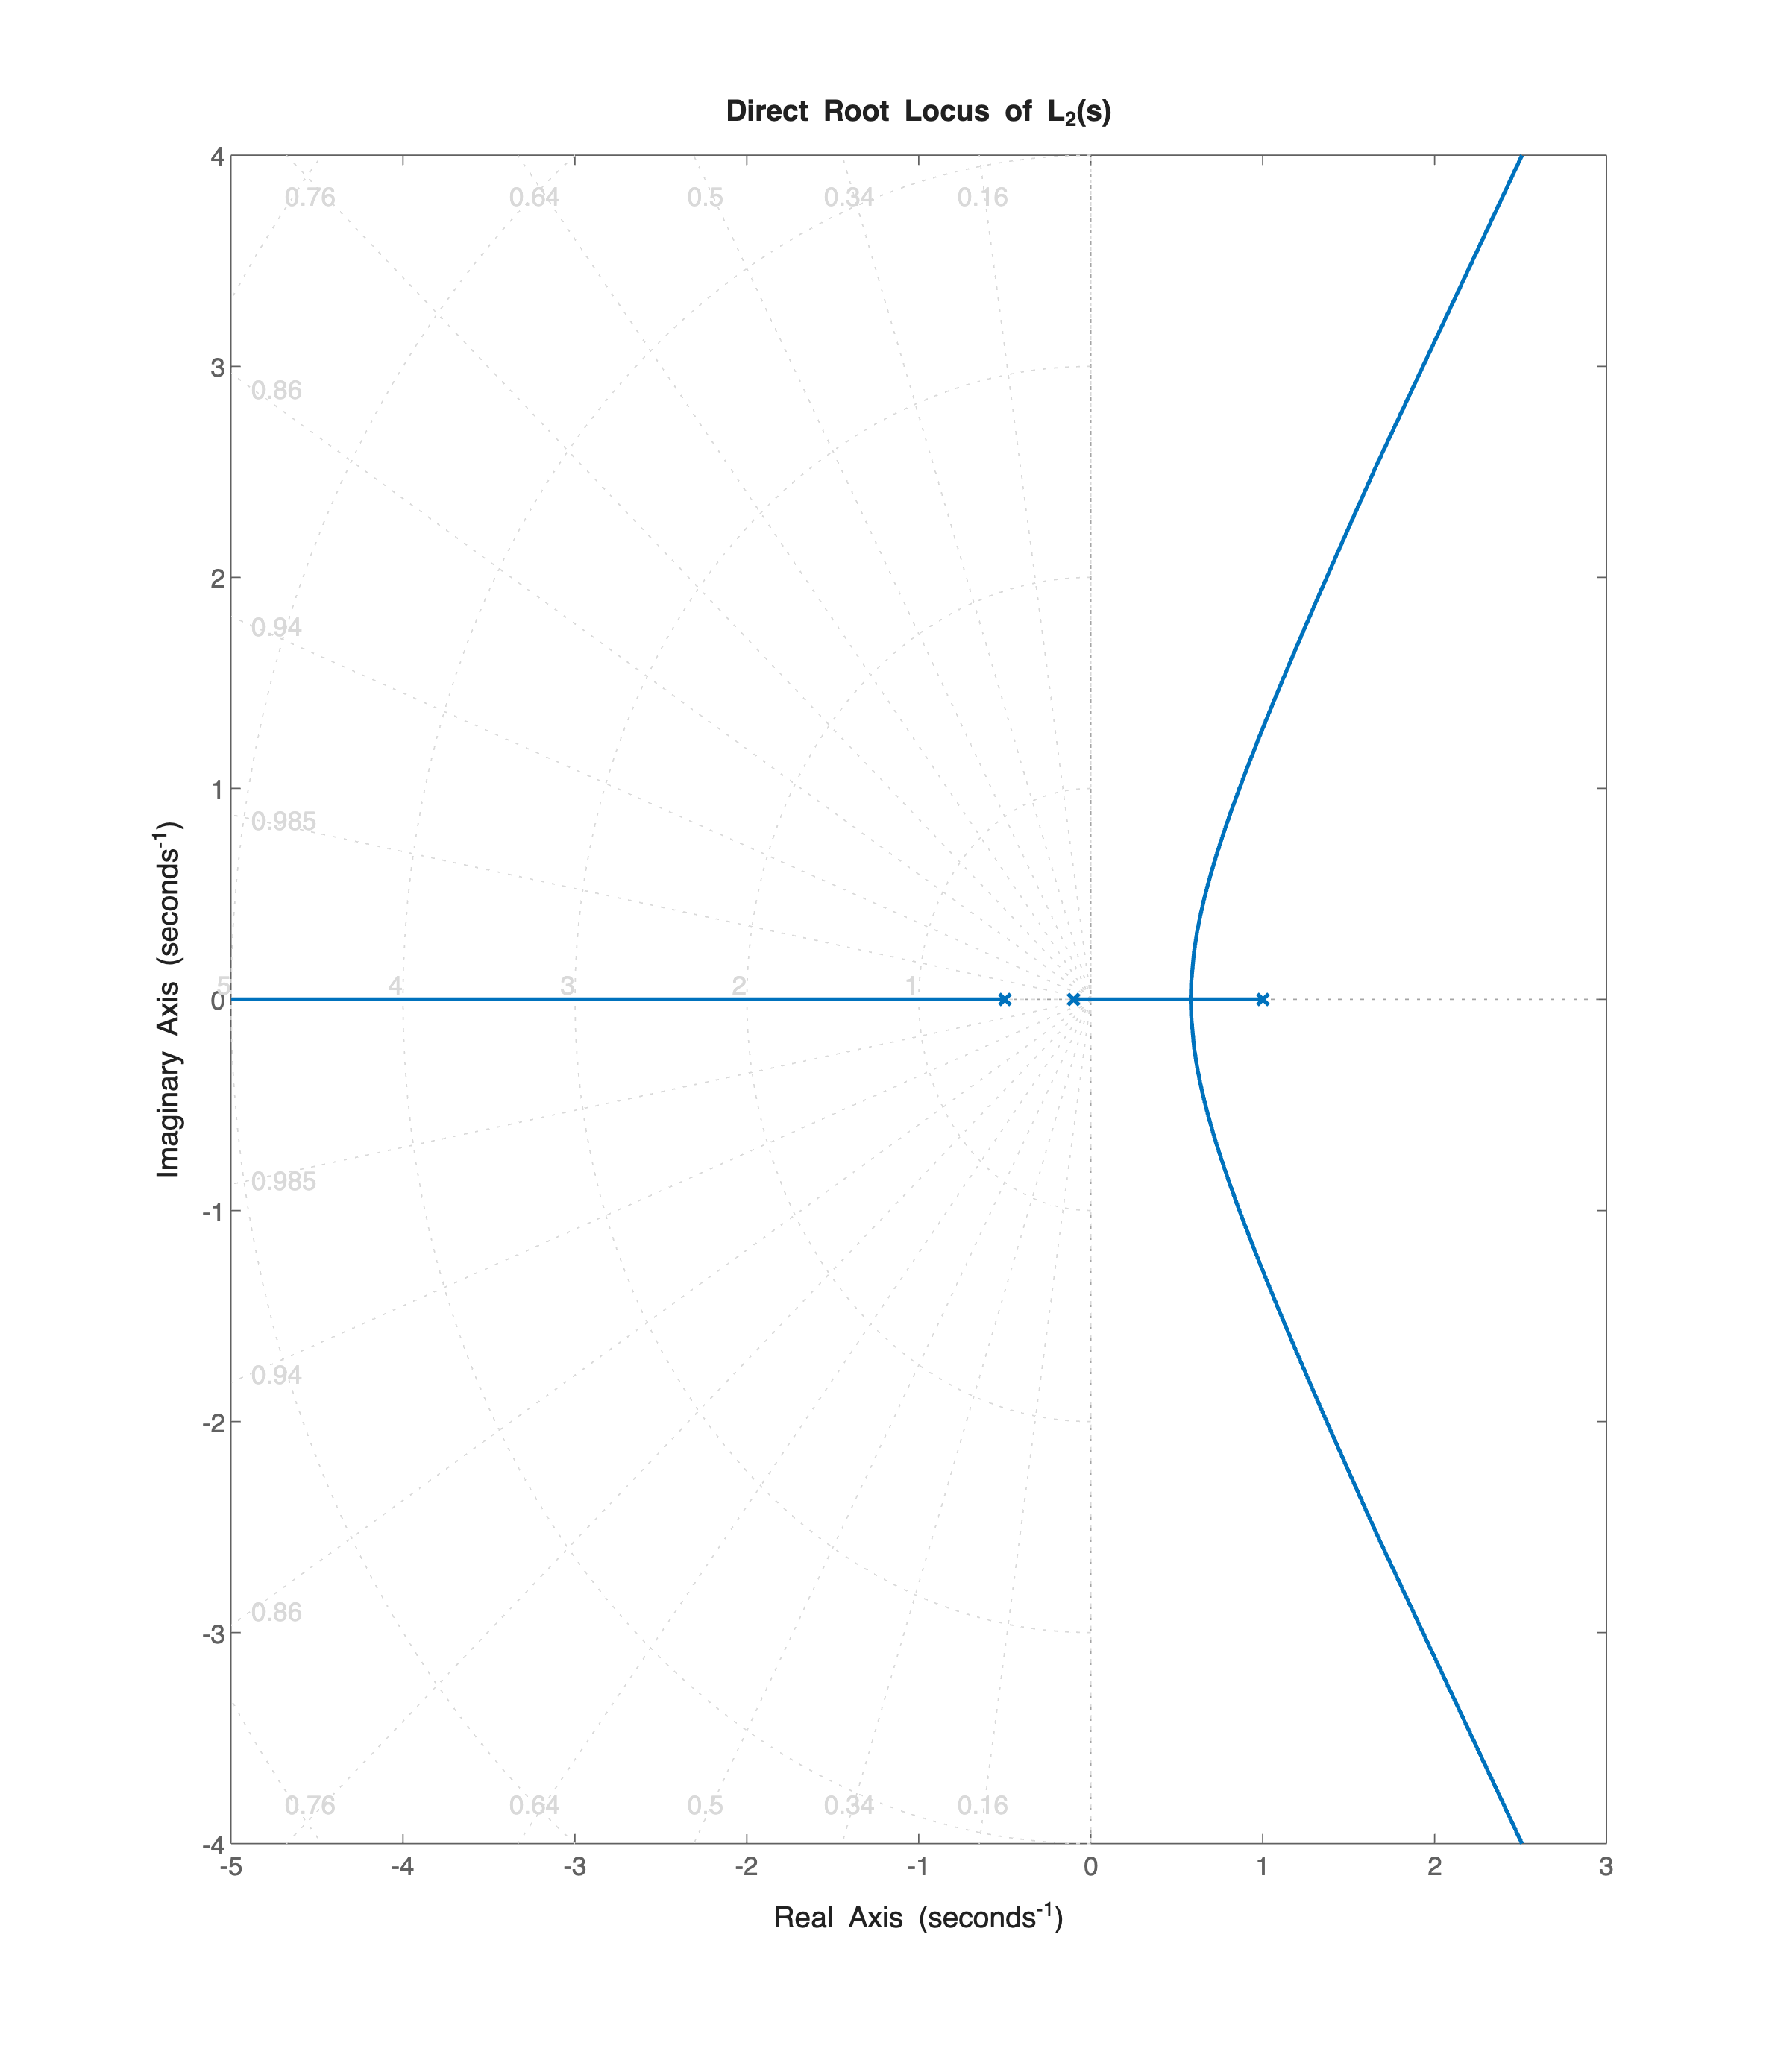

hf1 = figure('Units','centimeters','Position',[0.01, 0.01, 24, 28]);
rlpH1 = rlocusplot(hf1, -Gs);
title("Direct Root Locus of L_2(s)");
rlpH1.Responses(1).LineWidth = 1.5;
sgrid 

**Remark**: This time we are analysing the Direct Root Locus of $G(s)$. 

As you can notice, using a pure proportional controller with negative gain ($\mu_2<0$) it is not possible to stabilise the system $G(s)$. We need a different structure for $C_2(s)$, adding some poles and zeros, with the aim to modify the root locus, in such a way that at least a portion of all the three locus branches originating from the open-loop poles is in the Left Half Plane (LHP) in the complex plane.

#### **Adding Poles and Zeros to the Stabilising Controller  - Moving the Centroid**

**A Simple Strategy - Moving the Centroid**

First of all, we must consider the case $\mu_2<0$ only.. The other starting configuration (i.e., $\mu_2>0$) does not allow for a stabilising solution, due to the locus branch, originating from the RHP pole,  being fully in the RHP plane.

- The **key-idea** is **to add zeros and poles** with the aim **to "move"** the **centroid** of the asymptotes and the **singular** **point**, belonging to the locus branch originating from the RHP pole, pushing both into the LHP plane.

**The centroid of the asymptotes**: given a proper transfer function $G(s)$, with $m$ zeros and $n$ poles (and $m\le n$), tthe $n-m$ asymptotes of the root locus intersect the real axis on the so-called **centroid**


$$x_a = \frac{1}{n-m}\, \left(\sum_{j=1}^{m} z_j - \sum_{i=1}^{n} p_i \right)$$


(refer to Part 9, slide 74 of the course material).

The centroid depends on the poles' sum and the zeros' sum but with the opposite sign. To bring the centroid inside the LHP plane, a straightforward approach could be cancelling with zeros the poles in the LHP plane very close to the origin and inserting new poles far away from the origin in the LHP.

Let's illustrate the strategy with a few examples. Consider the following stabilising-controller candidates:

- 
$$\hat{C}_{2\,a}(s) = -\mu_2\,\frac{(1+10\,s)\,(1+2\,s)}{(1+s)\,\left(1+\frac{s}{2}\right)} \; \Longrightarrow \; \hat{L}_a(s) = \hat{C}_{2\,a}(s) \cdot G(s) = \frac{-4\mu_2}{(1-s)\,(1+s)\,\left(1+\frac{s}{2}\right)} = \frac{8 \mu_2}{(s-1)\,(s+1)\,(s+2)} \quad \Longrightarrow \;x_a = \frac{1}{3}\, \big[ +1-2-1\big] = -\frac{2}{3}$$


- 
$$\hat{C}_{2\,b}(s) = -\mu_2\,\frac{(1+10\,s)\,(1+2\,s)}{\left(1+\frac{s}{10}\right)\,\left(1+\frac{s}{2}\right)} \; \Longrightarrow \; \hat{L}_b(s) = \hat{C}_{2\,b}(s) \cdot G(s) = \frac{-4\mu_2}{(1-s)\,\left(1+\frac{s}{10}\right)\,\left(1+\frac{s}{2}\right)} = \frac{80 \mu_2}{(s-1)\,(s+10)\,(s+2)}\; \Longrightarrow \; x_a = \frac{1}{3} \, \big[+1-10-2\big] = -\frac{11}{3}$$


- 
$$\hat{C}_{2\,c}(s) = -\mu_2\,\frac{(1+10\,s)\,(1+2\,s)}{\left(1+\frac{s}{20}\right)^2} \; \Longrightarrow \; \hat{L}_c(s) = \hat{C}_{2\,c}(s) \cdot G(s) = \frac{-4\mu_2}{(1-s)\,\left(1+\frac{s}{20}\right)^2} = \frac{1600 \mu_2}{(s-1)\,(s+20)^2}\; \Longrightarrow \; x_a = \frac{1}{3}\, \big[+1-20-20\big] = -13$$


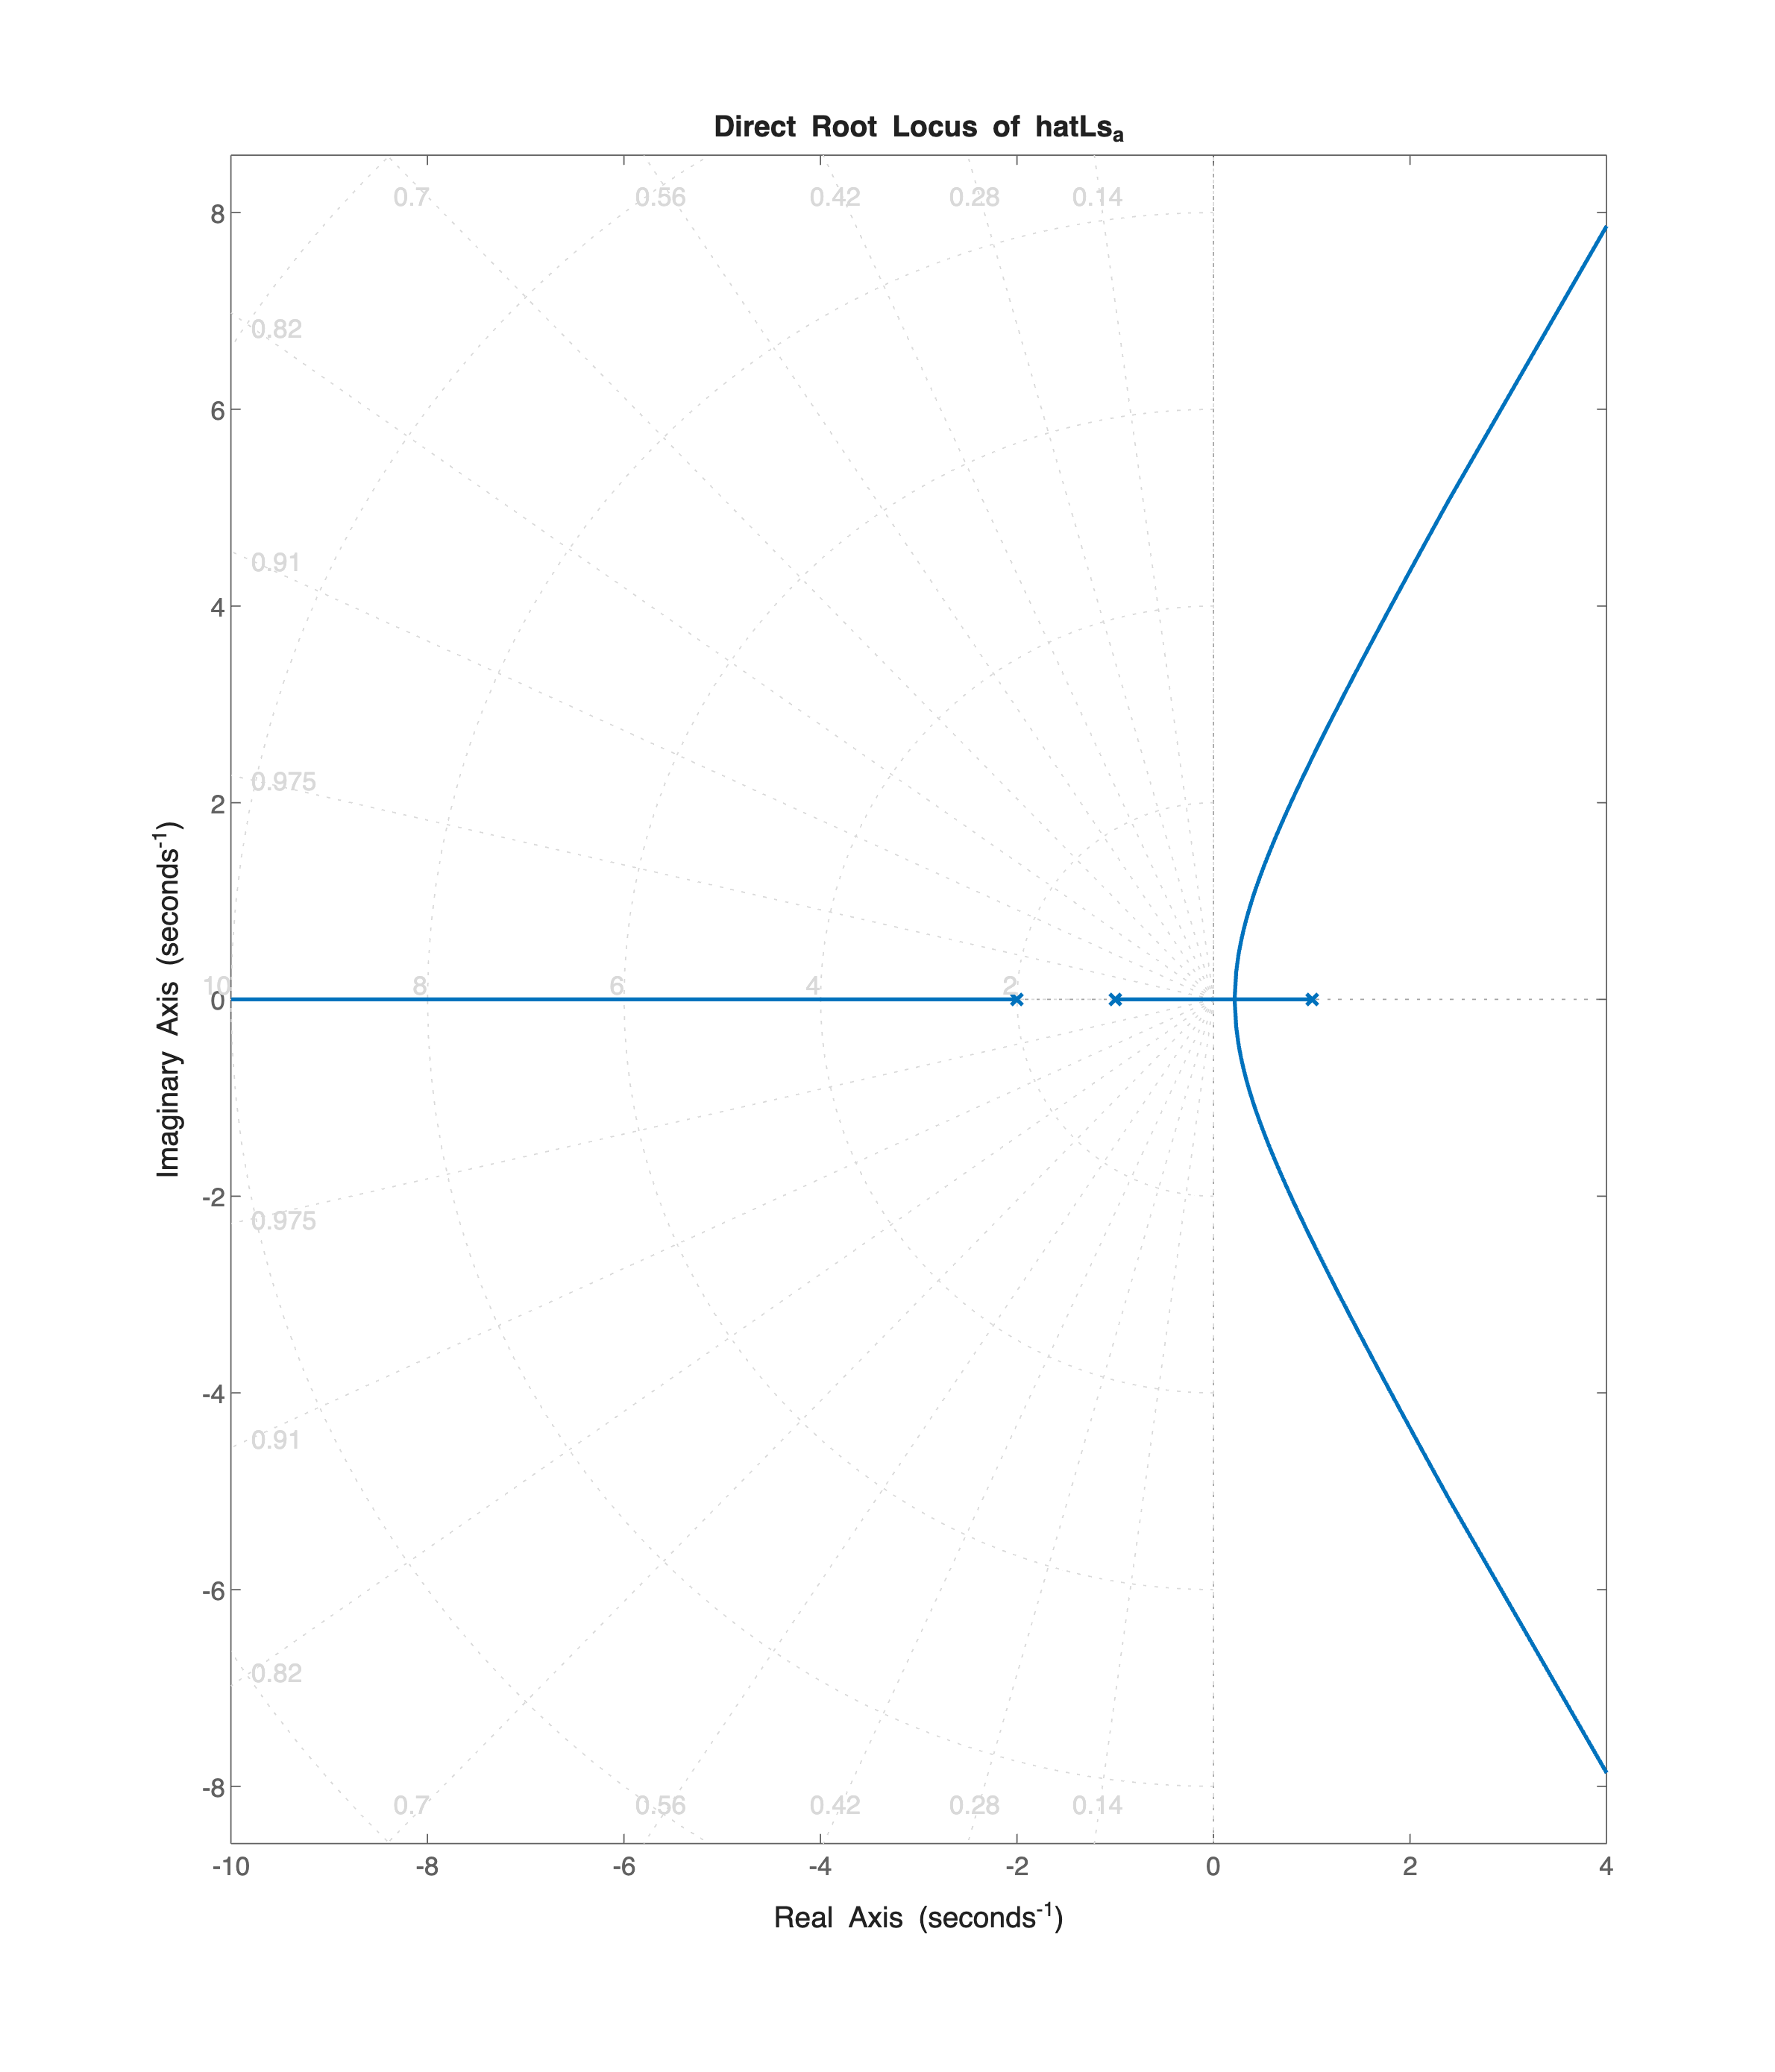


Gs = 4/((1-s)*(1+10*s)*(1+2*s)); % the unstable process G(s)
Cstrial2 = (1+10*s)*(1+2*s)/((1+s/10)*(1+s/2));
Cstrial3 = (1+10*s)*(1+2*s)/((1+s/20)*(1+s/20));
Cstrial1 = (1+10*s)*(1+2*s)/((1+s)*(1+s/2));

hatLsa = minreal(Cstrial1*Gs);
hatLsb = minreal(Cstrial2*Gs);
hatLsc = minreal(Cstrial3*Gs);

hf2 = figure('Units','centimeters','Position',[0.01, 0.01, 24, 28]);
rlpH2 = rlocusplot(hf2, -hatLsa);
title("Direct Root Locus of hatLs_a");
rlpH2.Responses(1).LineWidth = 1.5;
grid on; axis equal
xlim([-10, +4]);

**No way to stabilise** the closed-loop system.

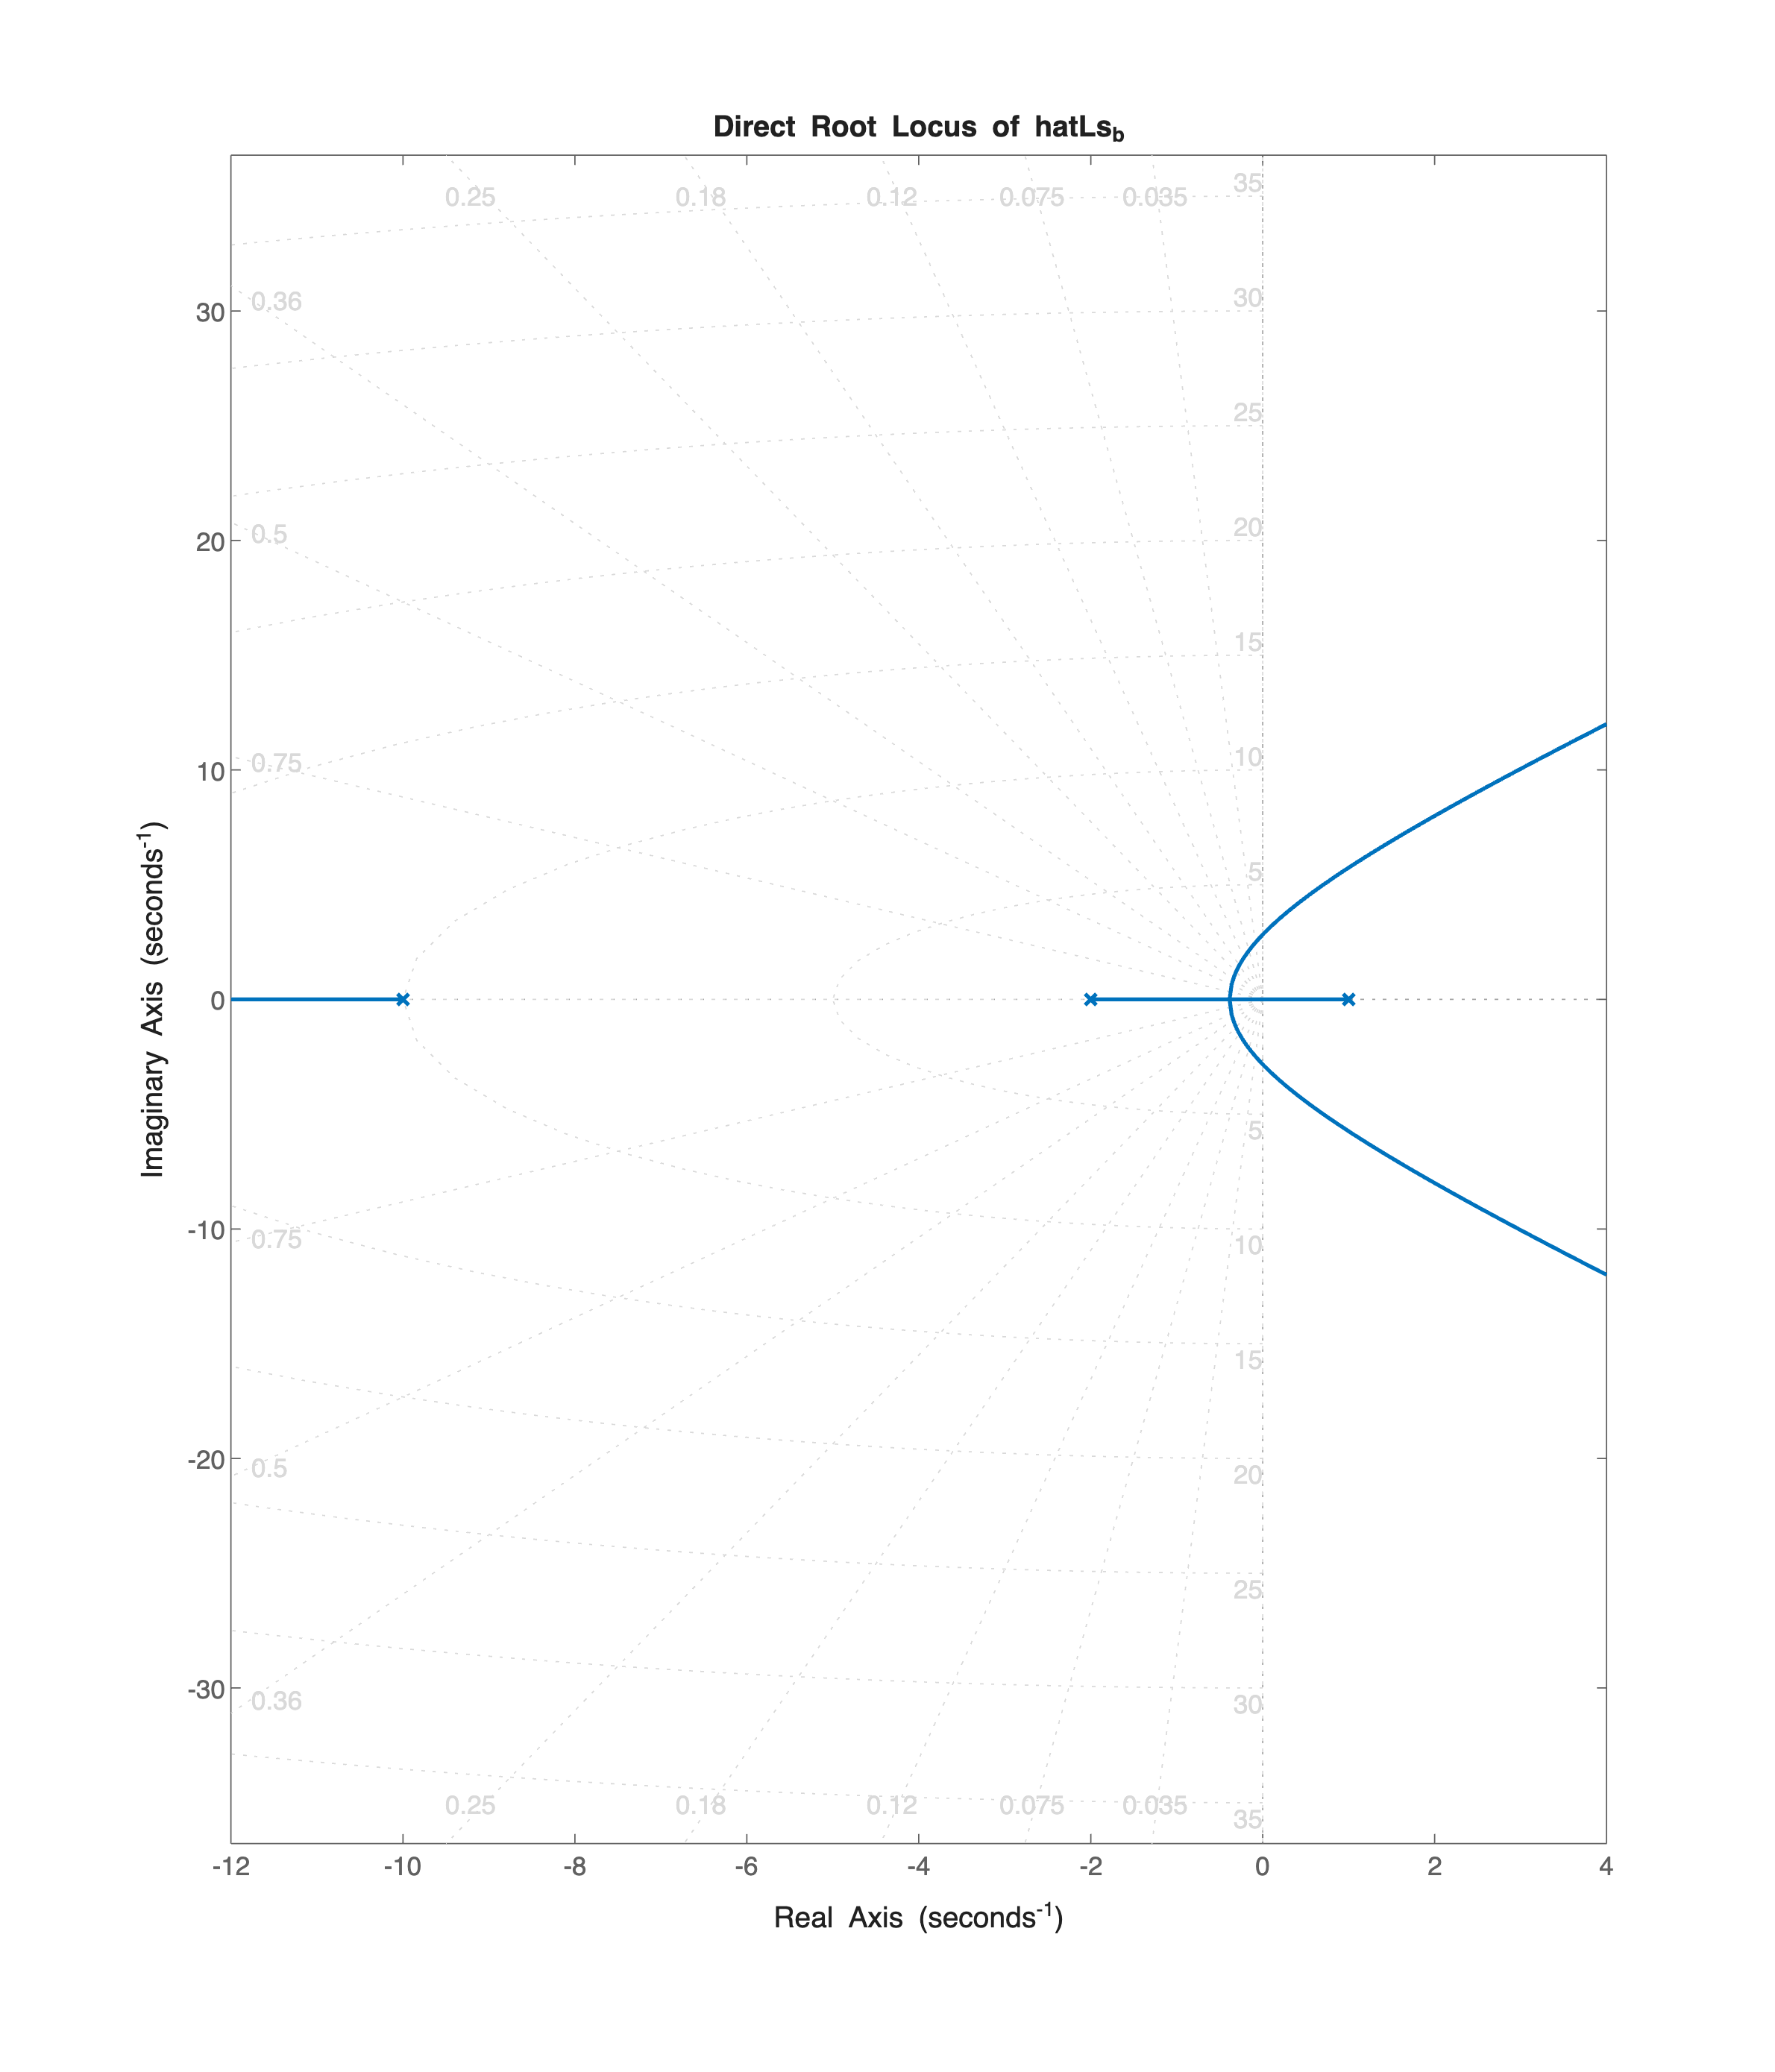

hf2 = figure('Units','centimeters','Position',[0.01, 0.01, 24, 28]);
rlpH2 = rlocusplot(hf2, -hatLsb);
title("Direct Root Locus of hatLs_b");
rlpH2.Responses(1).LineWidth = 1.5;
axis equal; grid on
 xlim([-12, +4]);

This time, a **small** **portion** of the root locus corresponds to an **asymptotically** **stable** closed-loop system.

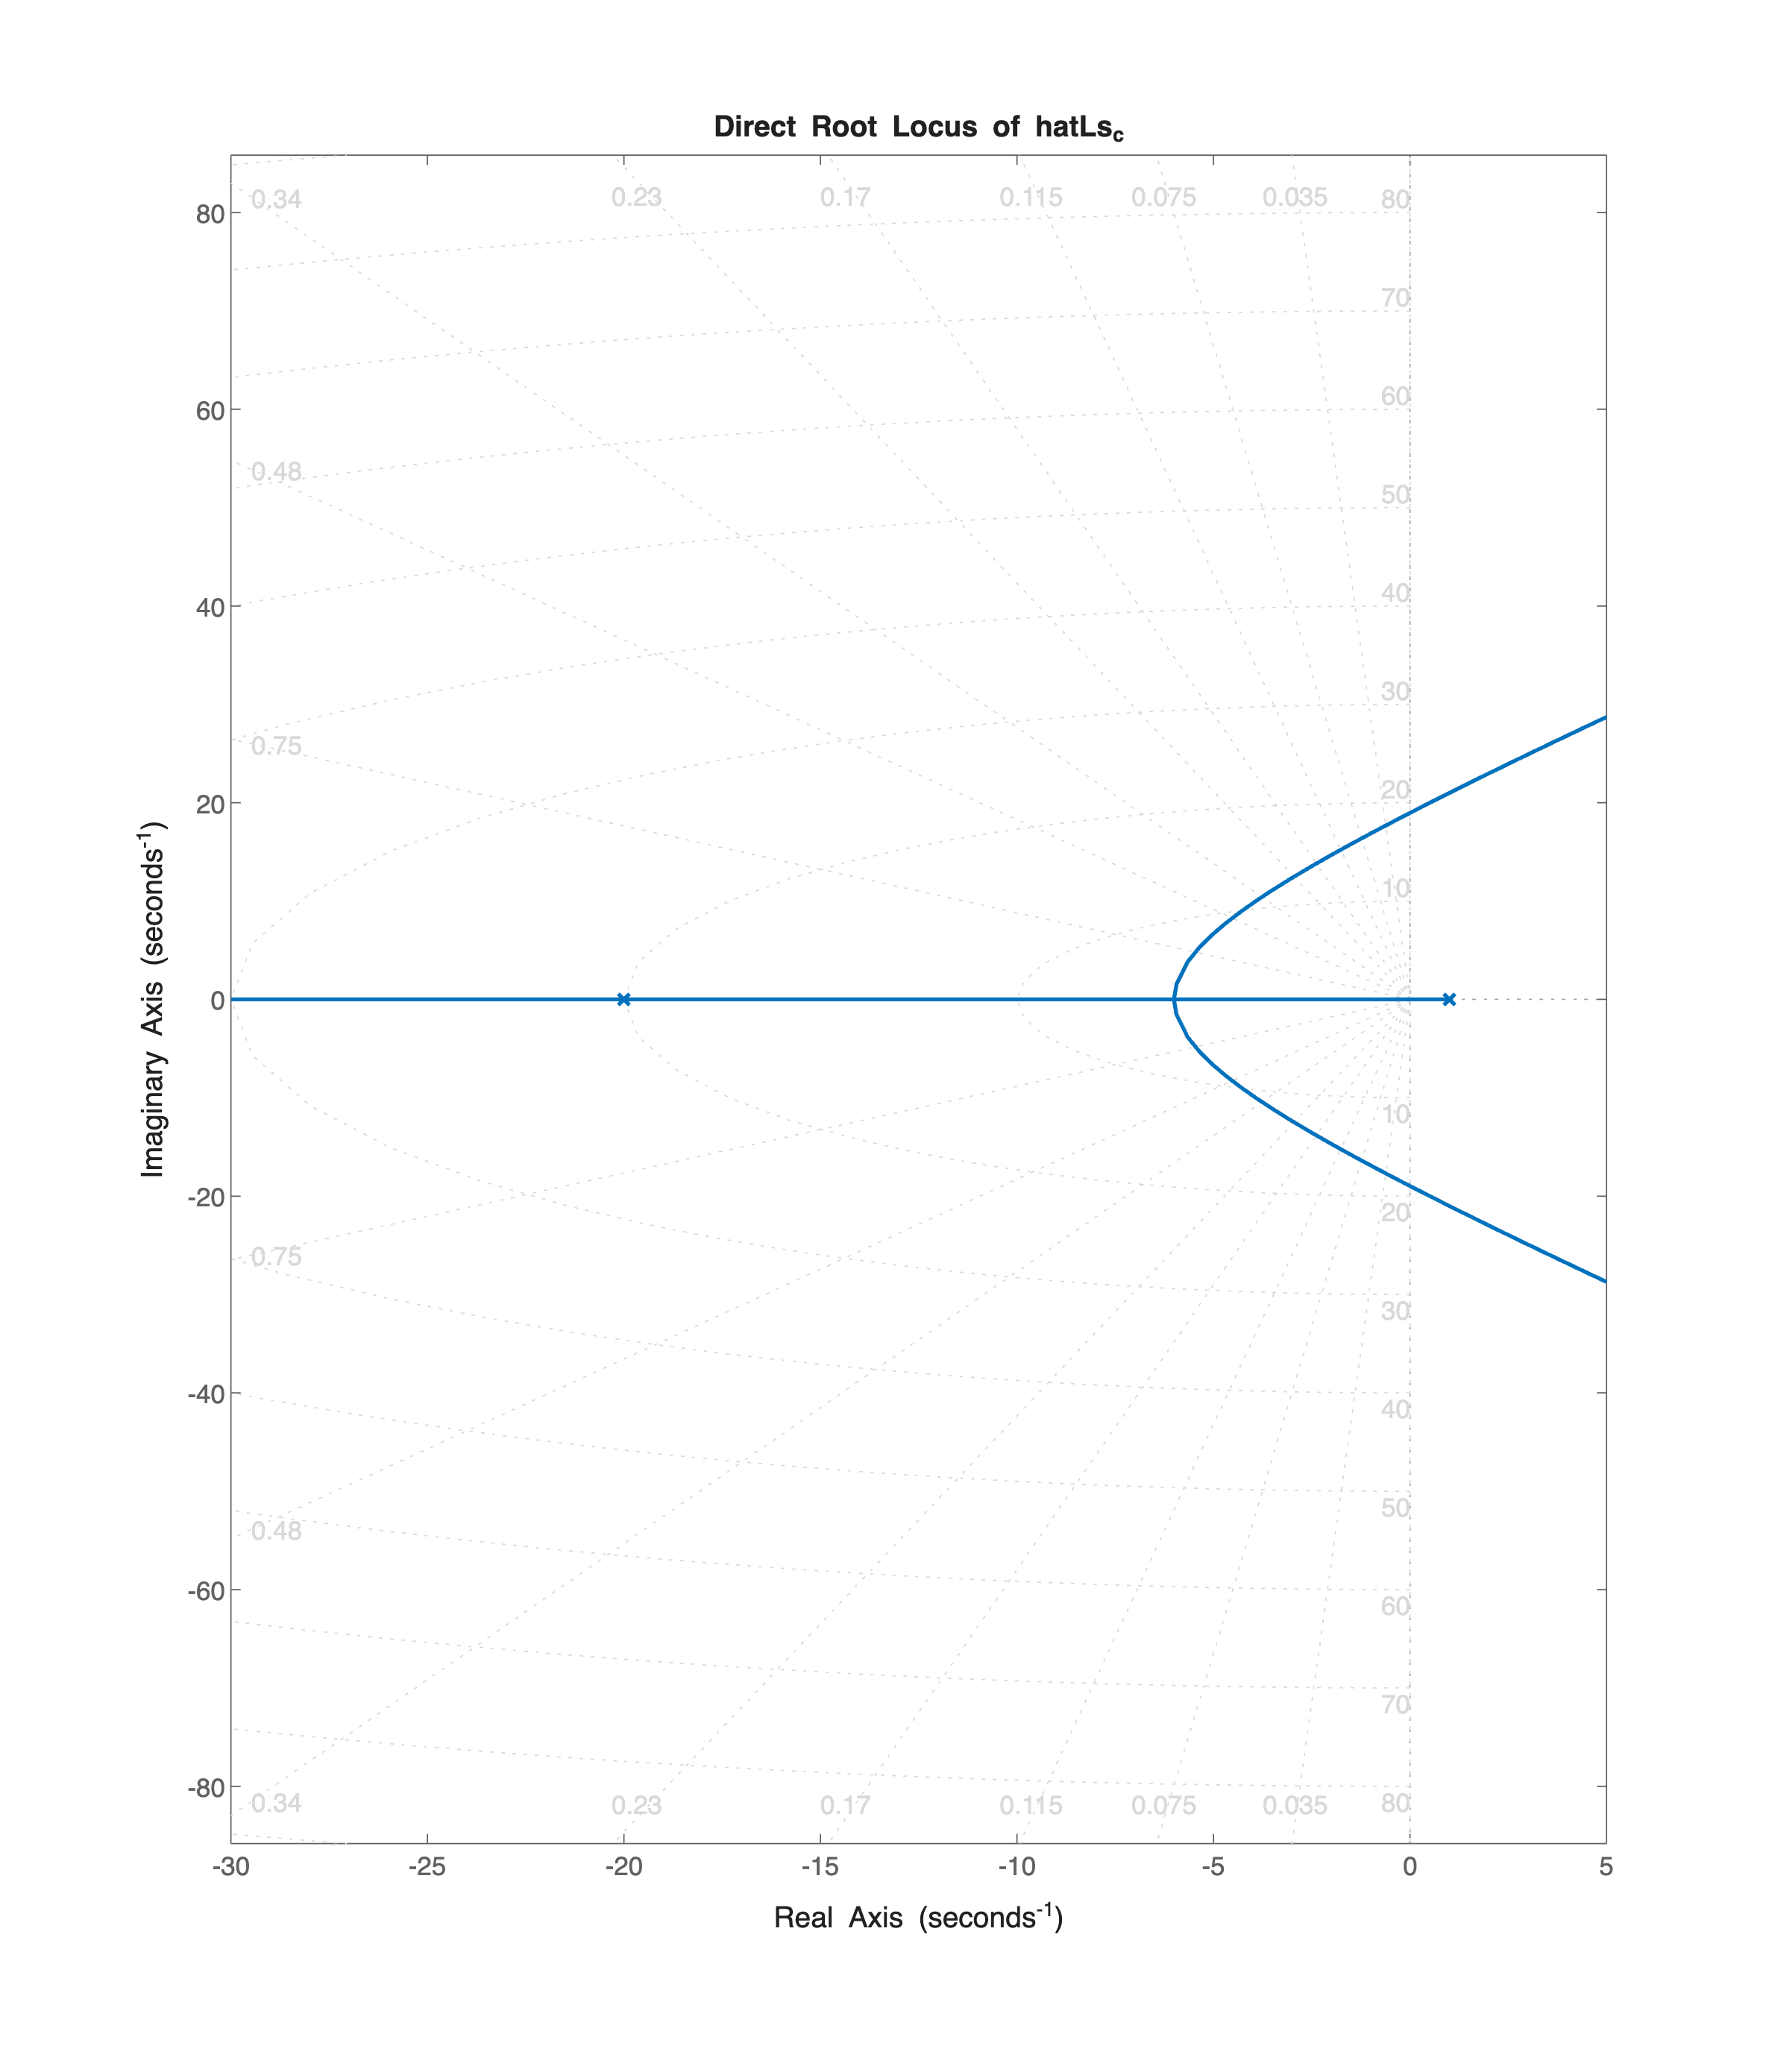

hf3 = figure('Units','centimeters','Position',[0.01, 0.01, 24, 28]);
rlpH3 = rlocusplot(hf3, -hatLsc);
title("Direct Root Locus of hatLs_c");
rlpH3.Responses(1).LineWidth = 1.5;
axis equal; xlim([-30, +5]);grid on

A **larger** **portion** of the root locus (compared with the previous case) corresponds to an **asymptotically** **stable** closed-loop system.

The latter is the best proposal so far for the inner controller $C_2(s)$.  What are the values of the gain $\mu_2$ allowing the asymptotic stability at closed-loop for $L_2(s)$? Two alternatives:

- looking for approximate bounds for the stabilising set of gain $\mu_2$ values (exploiting the Inverse Root Locus of $L_2(s)$ and the MATLAB command `rlocfind` );

- computing the bounds of the stabilising set of gain $\mu_2$ values, using the Routh-Hurwitz criterion.

#### The Bounds of the Stabilising Gain Set - the Routh-Hurwitz Criterion Approach

The closed-loop poles equation in the latter scenario is as follows:


$$1+\hat L_c(s) = 0 \;\Longrightarrow \;  (1-s)\,\left(1+\frac{s}{20}\right)^2-4\,\mu_2 = 0 \; \Longrightarrow \;s^3+39\,s^2+360\,s +400\,(400\,\mu_2-1)$$


syms x mu2
px = (1-x)*(1+x/20)^2-4*mu2;
collect(simplify(px),x)*(-400)

$$ans = x^{3}+39\,x^{2}+360\,x+1600\,\mu_{2}-400$$

Let's fill the Routh table


$$\begin{array}{c|cc}
3 & 1 & 360\\2 & 39 &400\,(400\,\mu_2-1) \\
1& \alpha \\
0& 400\,(400\,\mu_2-1)
\end{array} \qquad \alpha = \frac{39\cdot 360 -400\,(400\,\mu_2-1)}{39} = \frac{14440}{39}-\frac{160000 \, \mu_2}{39}$$


alphaP = simplify((39*360-400*(400*mu2-1))/39)

$$alphaP = \frac{14440}{39}-\frac{160000\,\mu_{2}}{39}$$

According to the Routh-Hurwitz theorem, in order to guarantee asymptotic stability the following inequalities must hold


$$\left\{ \begin{array}{rcl}
14440-160000\,\mu_2 &>&0 \\
400\,\mu_2-1 &>&0
\end{array} \right. \quad \Longrightarrow \quad 
\left\{ \begin{array}{rcl}
\mu_2 &<& \frac{14440}{160000} = \frac{361}{4000} \approx 9.02\cdot 10^{-2}\\
\mu_2 &>& \frac{1}{400} = 2.50\cdot 10^{-3}
\end{array} \right. \quad \Longrightarrow \quad 2.50\cdot 10^{-3} < \mu_2 < 9.02\cdot 10^{-2}$$


In conclusion, we can guarantee closed-loop asymptotic stability if and only if $2.50\cdot 10^{-3} < \mu_2 < 9.02\cdot 10^{-2}$.

#### **A Different Strategy**

Consider, for the moment, the modified transfer function $\hat{L}_2(s)$:


$$\hat{L}_2(s) = 4 \mu_2\,\frac{(1+10\,s)\,(1+2\,s)}{(1-s)\,(1+10\,s)\,(1+2\,s)\,\left(1+\frac{1}{20}s\right) } = 4\mu_2 \,\frac{1}{(1-s)\,\left(1+\frac{1}{20}s\right)}\;\Longrightarrow\; \hat{L}_2(s) =\hat  \varrho\,\frac{1}{(s-1)\,\left(s+20\right)$$


with $\hat \varrho = -80 \mu_2$. Thus, $\mu_2 <0 \;\Longrightarrow\;\hat \varrho >0$.

**Note**: the actual controller looks like an improper transfer function, for the moment: $\hat C_2(s) = \frac{(1+10\,s)\,(1+2\,s)}{\left(1+\frac{s}{20}\right)}$

**We will solve this issue later.**

**The Rationale of This Proposal**

- The key idea is to push the root locus deeper in the Left Half Plane than we did using the previously proposed approaches.

- Considering this modified transfer function helps to find easily a partial solution (the root locus of $\hat{L}_2(s)$ is easy to draw, and so are also the main features of such a locus, i.e., the centroid, the critical point on the Direct Locus. Also, the computation of the gain $\hat \varrho$ allowing the placement of the closed-loop poles in properly chosen positions is very straightforward.

- Having found a good gain value $\tilde \varrho$ for this modified root locus problem, we add another term to the controller $\hat C_2(s)$, making it finally a realisable transfer function (a proper transfer function). The new term adds another pole to the controller, in such a way to keep almost unaltered the outcome of the previous step of the procedure: i.e., locally the new root locus is quite similar to the locus of the modified transfer function $\hat{L}_2(s)$, and two of the poles of the new $L_2(s)$ transfer function, corresponding to the gain $\tilde \varrho$, are close enough to the pole positions chosen for $\hat{L}_2(s)$.

- The new term is


$$\frac{1}{1+s\tau}\;,\quad 0<\tau\ll1$$


- Practically, the pole $p = -\frac{1}{\tau}$ should be at least "a decade far away" from the other poles in $\hat L_2(s)$, to obtain the desired effect. The only other constraint on the added pole is the asymptotic stability of the new closed-loop transfer function

The Direct Root Locus for $\hat L_2(s)$ is simple and the corresponding closed-loop transfer function is always asymptotically stable.

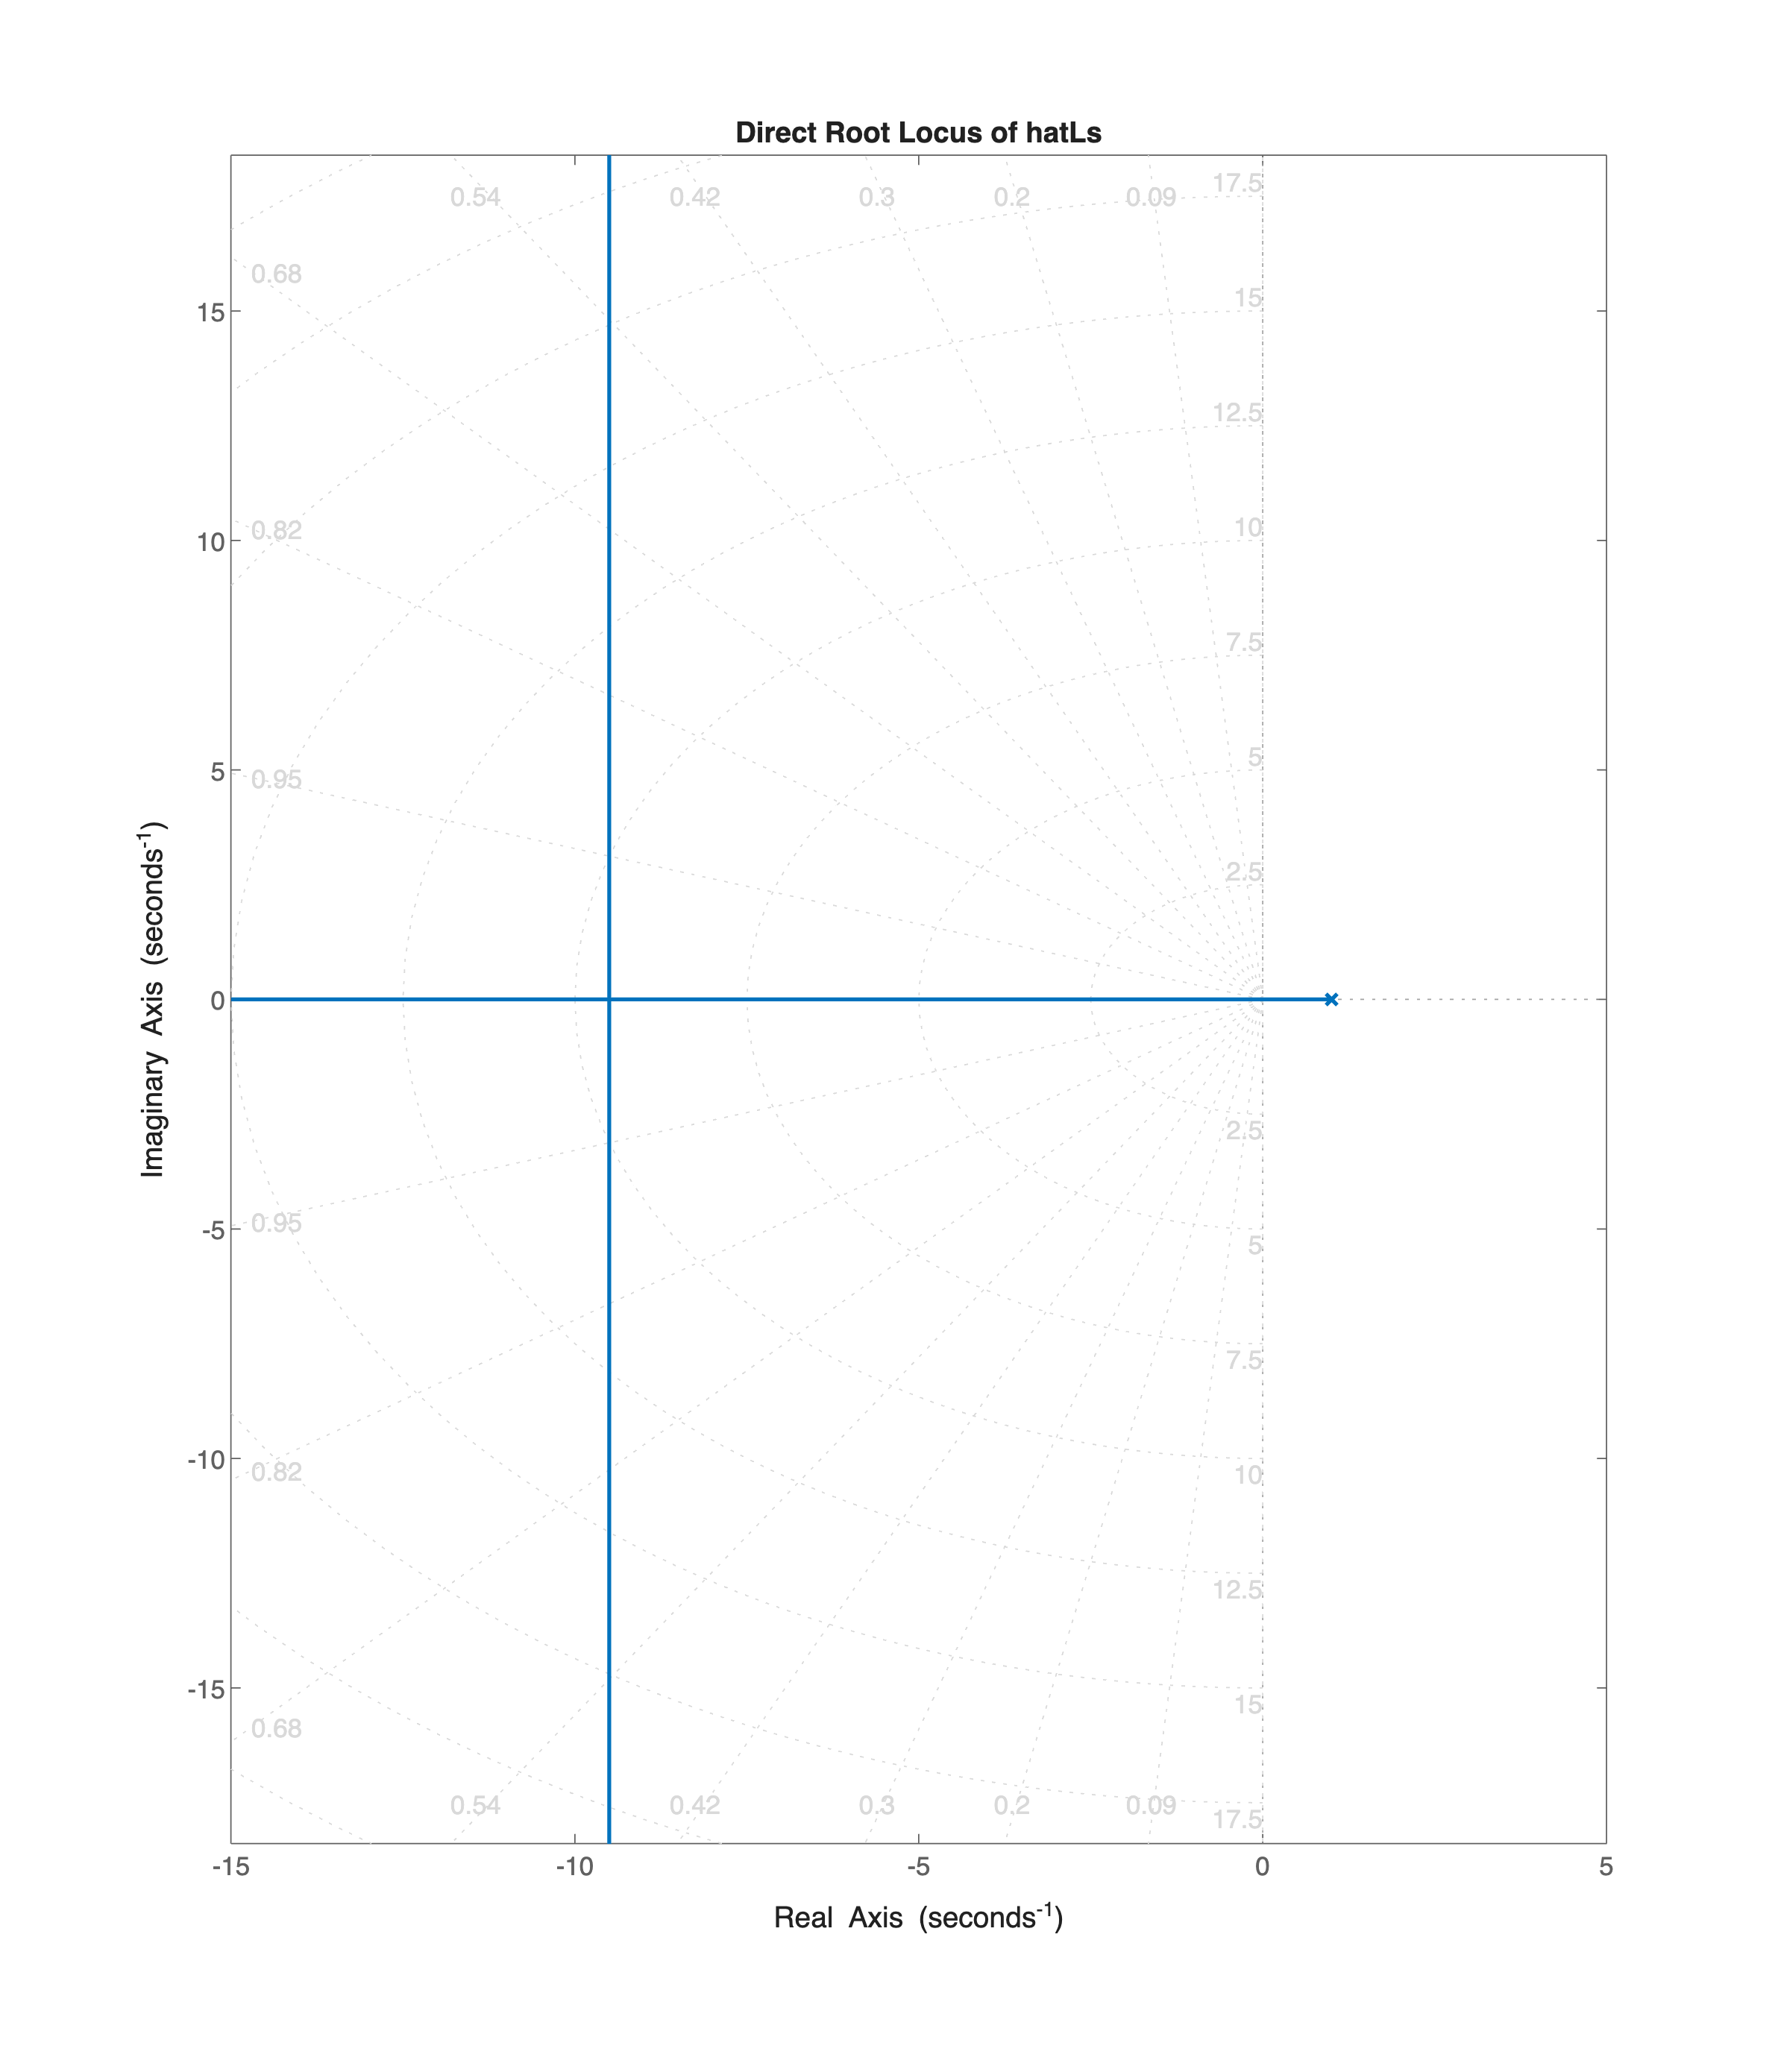

hatLs = 4/(1-s)/(1+s/20);

hf4 = figure('Units','centimeters','Position',[0.01, 0.01, 24, 28]);
rlpH4 = rlocusplot(hf4, -hatLs);
title("Direct Root Locus of hatLs");
rlpH4.Responses(1).LineWidth = 1.5;
axis equal; xlim([-15, +5]);grid on

%figure;rlocus(-hatLs);

Let's select the gain $\tilde \varrho$ such that the closed-loop poles are $p_{1,\,2} = -\frac{19}{2}$


$$\left\{ \begin{array}{rcl} 
(\bar s-1 )(\bar s+20) +\tilde \varrho &=& 0 \\
\bar s &=& -\frac{19}{2}
\end{array} \right. \quad \Longrightarrow \quad \tilde \varrho = \frac{441}{4} \;\Longrightarrow \; \tilde \mu = -\frac{441}{320}$$


syms x
px = (x-1)*(x+20);
tildeRHO = -simplify(subs(px, x, -19/2))

$$tildeRHO = \frac{441}{4}$$

tildeMU = -tildeRHO/80

$$tildeMU = -\frac{441}{320}$$

The closed-loop poles corresponding to $\tilde \mu_2$ are:

pole(feedback(double(tildeMU)*hatLs,1,-1))

ans =   -9.5000 + 0.0000i
  -9.5000 - 0.0000i


Now, let's insert the additional term, in order to have the controller as a proper transfer function


$$L_2(s) = \hat L_2(s) \cdot \frac{1}{1+s\,\tau} \; \Longrightarrow \; L_2(s) = 4\,\tilde \mu_2 \,\frac{1}{(1-s)\,\left(1+\frac{1}{20}s\right) } \cdot \frac{1}{1+\frac{s}{250} }\; \Longrightarrow \; C_2(s) = \tilde \mu_2 \, \frac{(1+10\,s)\,(1+2\,s)}{\left(1+\frac{1}{20}s\right)\, \left(1+\frac{s}{250} \right)}$$


L4s = hatLs*(1/(1+s/250))


L4s =
 
             -20000
  -----------------------------
  s^3 + 269 s^2 + 4730 s - 5000
 
Continuous-time transfer function.
Model Properties


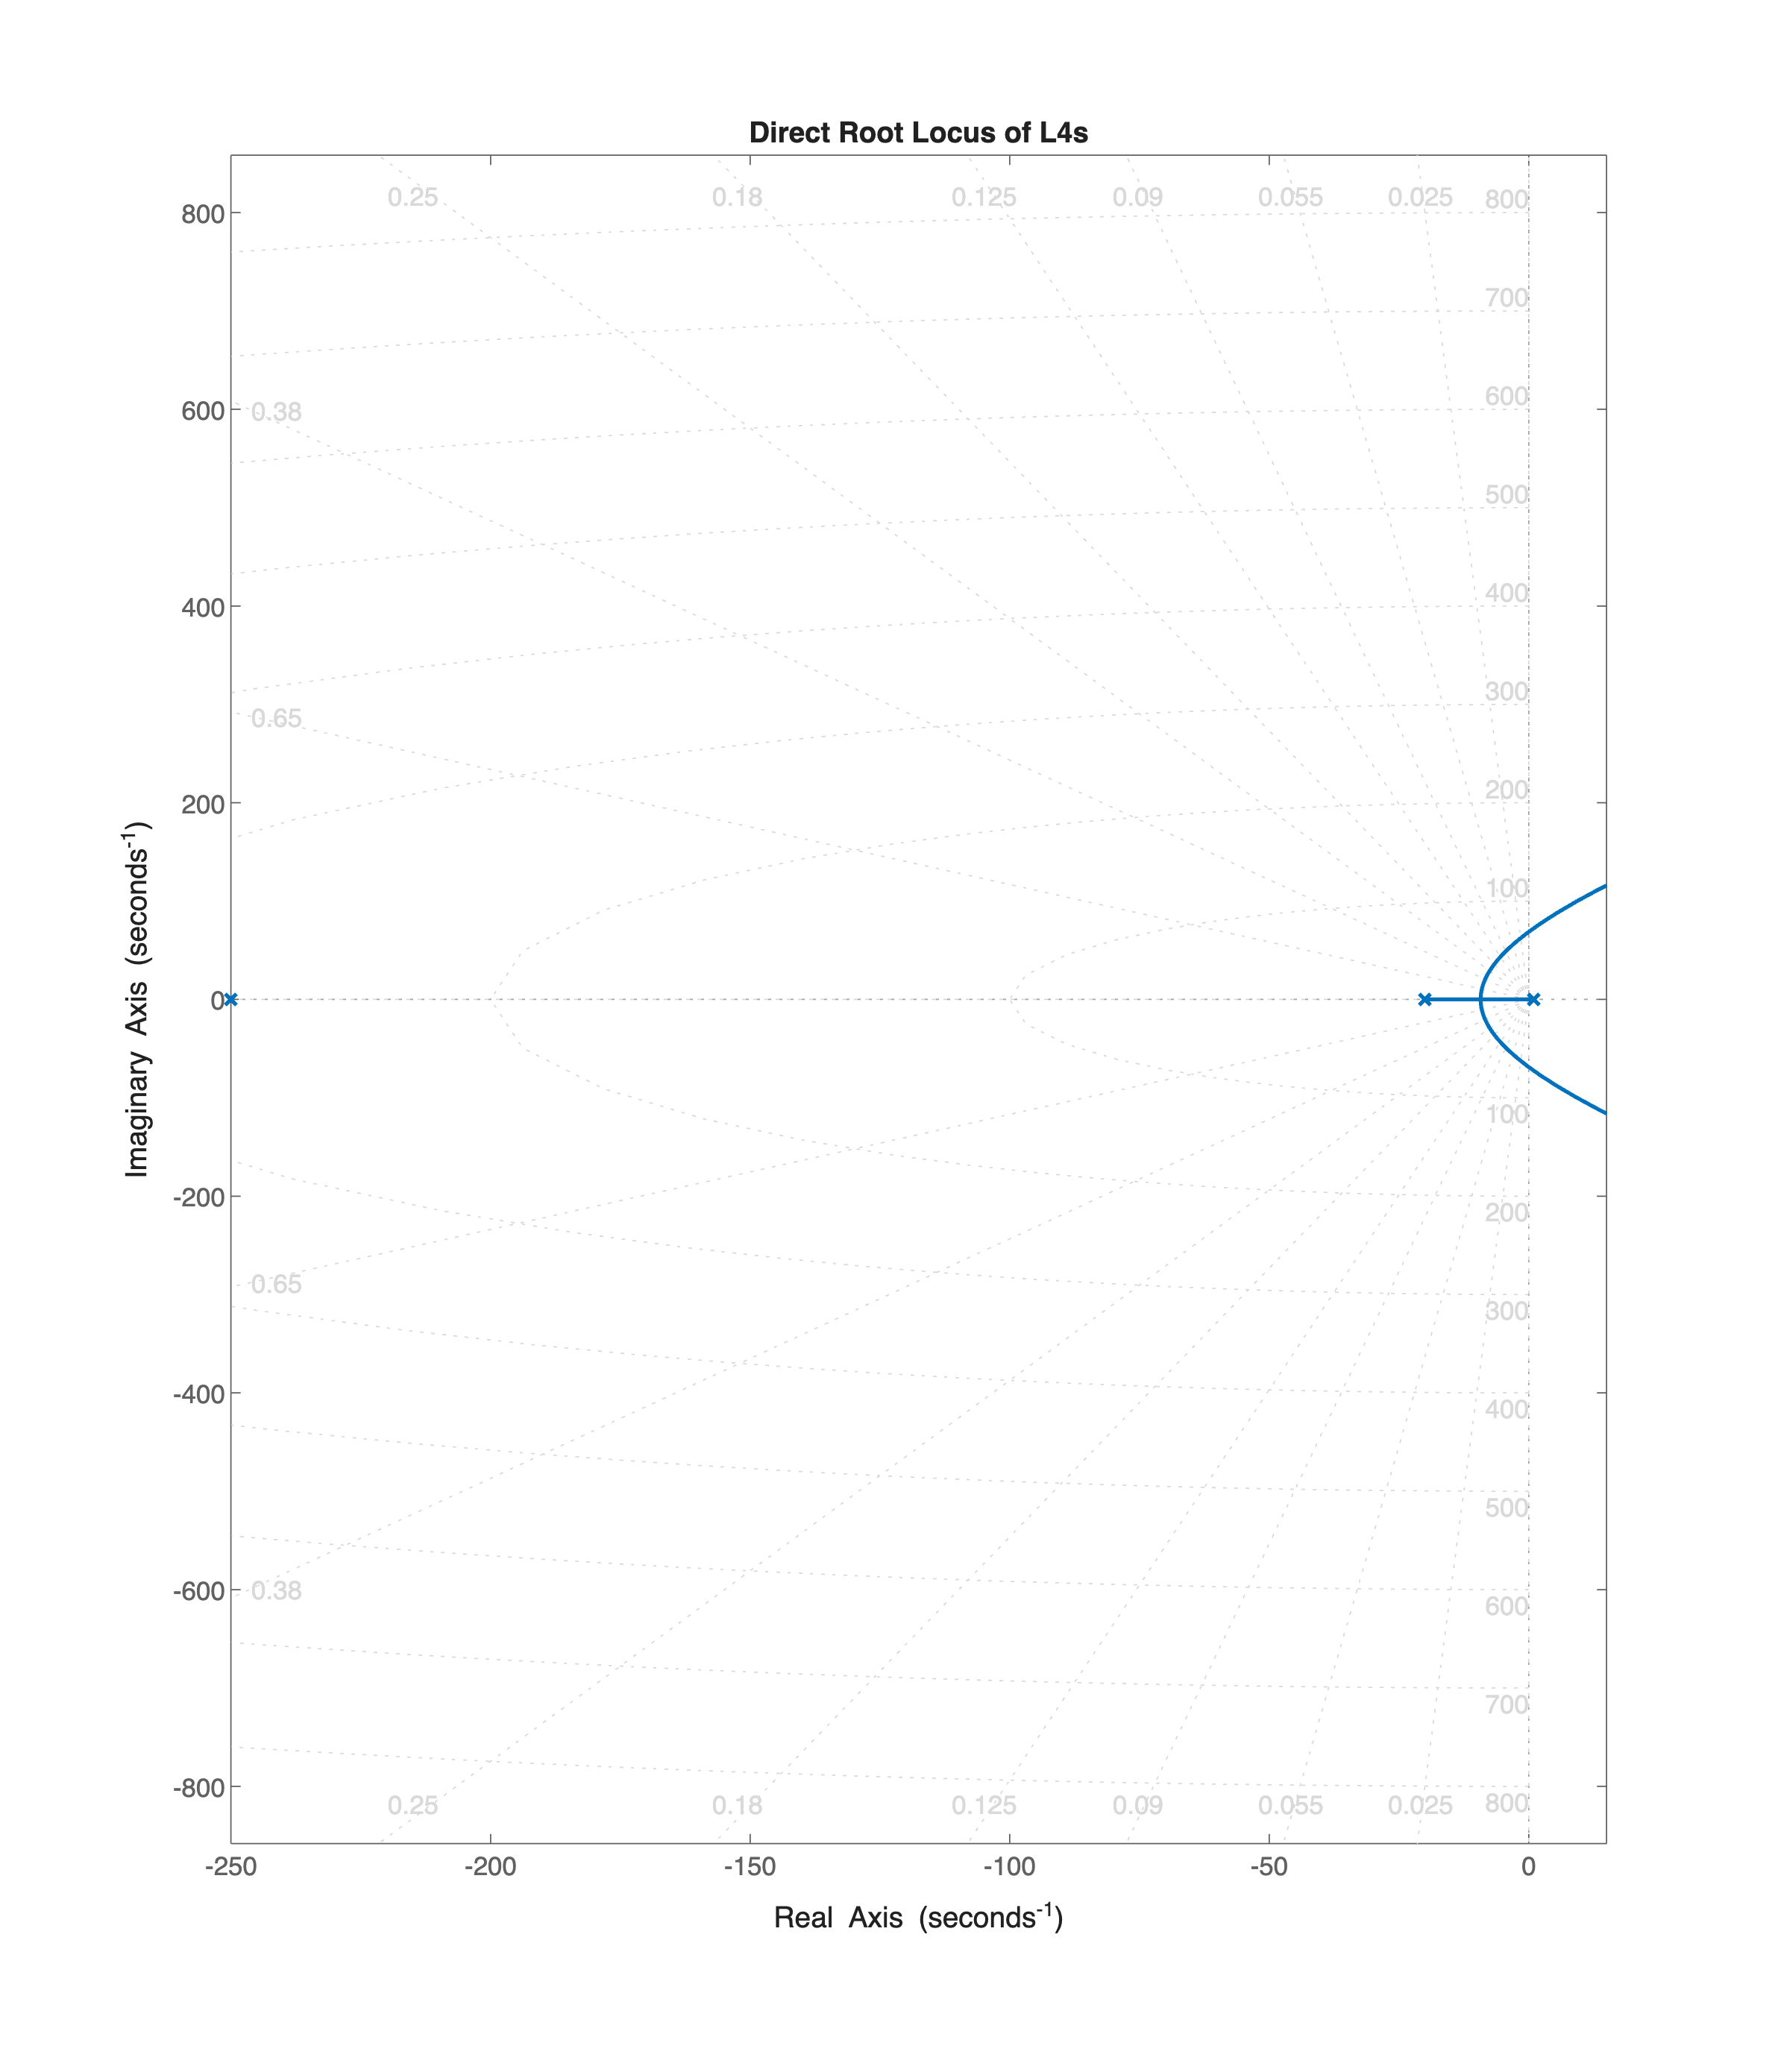

hf5 = figure('Units','centimeters','Position',[0.01, 0.01, 24, 28]);
rlpH5 = rlocusplot(hf5, -L4s);
title("Direct Root Locus of L4s");
rlpH5.Responses(1).LineWidth = 1.5;
axis equal; xlim([-250, +15]);grid on

Let's examine the **portion** of the root locus **closest** to the **origin** in the complex plane.

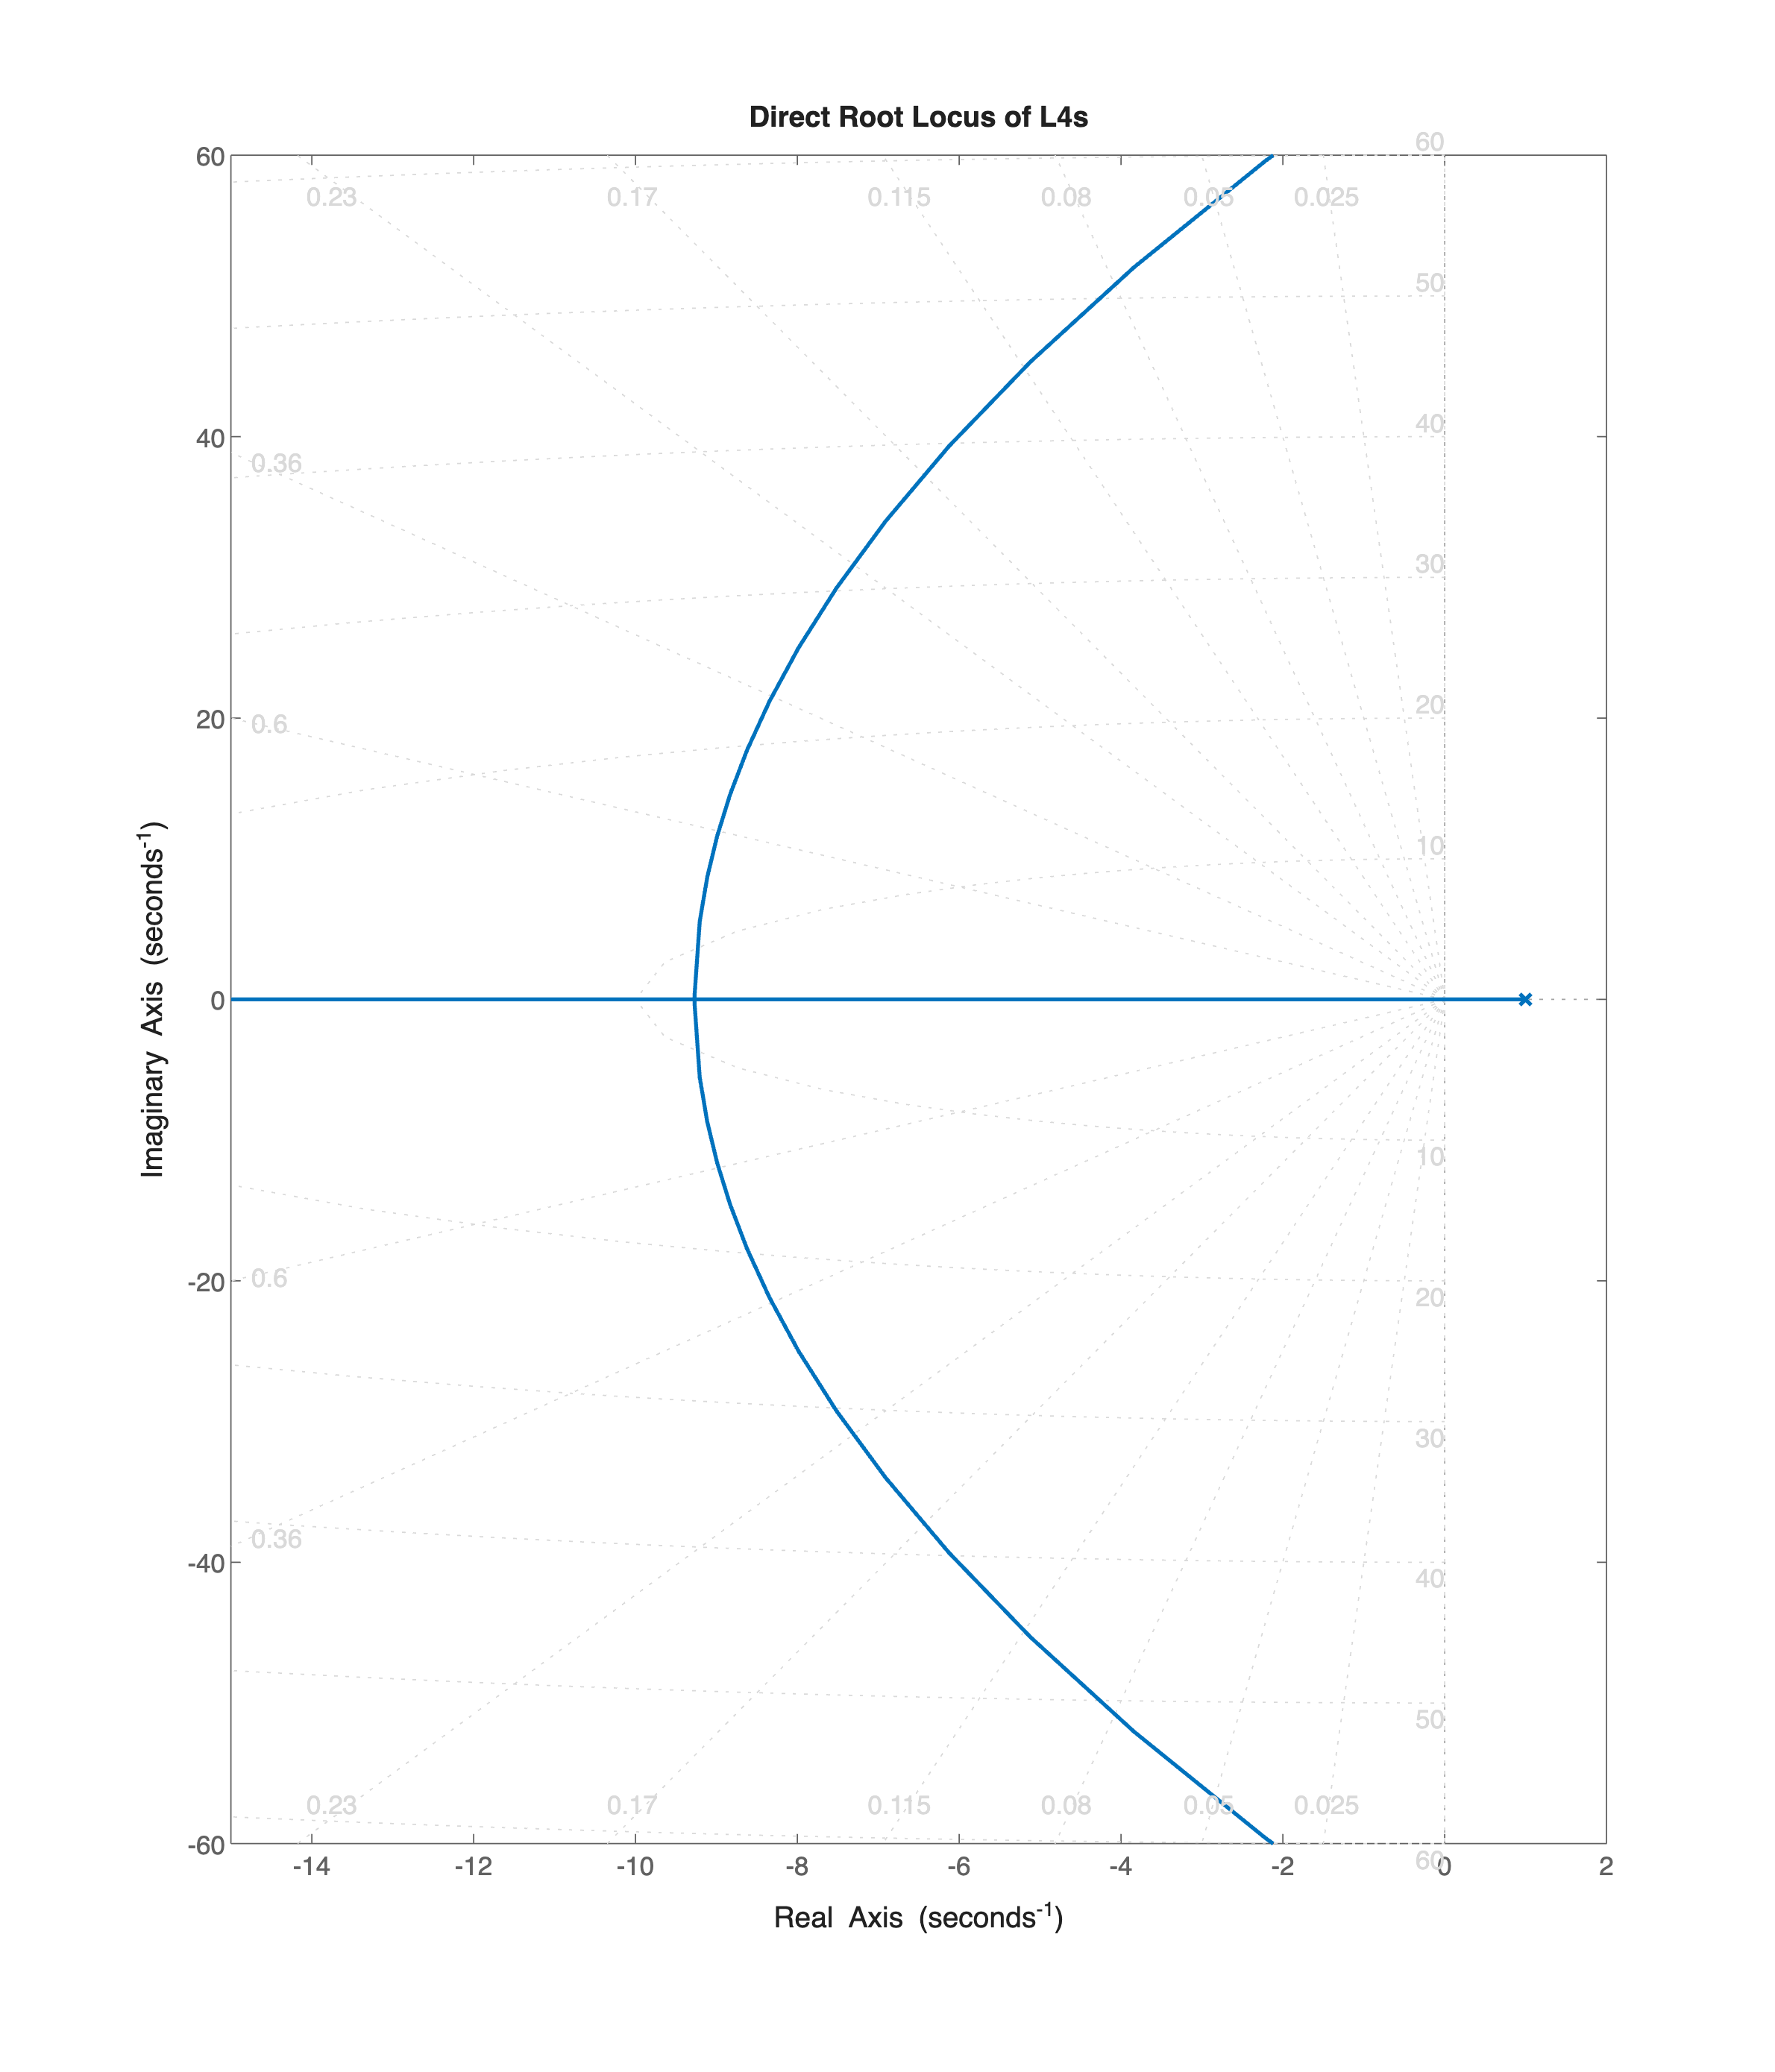

hf5B = figure('Units','centimeters','Position',[0.01, 0.01, 24, 28]);
rlpH5B = rlocusplot(hf5B, -L4s);
title("Direct Root Locus of L4s");
rlpH5B.Responses(1).LineWidth = 1.5;
xlim([-15, +2]); ylim([-60,  +60]); grid on

The inner controller is


$$C_2(s) = \tilde \mu_2 \, \frac{(1+10\,s)\,(1+2\,s)}{\left(1+\frac{1}{20}s\right)\, \left(1+\frac{s}{250} \right)}$$


barMu = -441/320;
C2s = barMu*(1+10*s)*(1+2*s)/(1+s/20)/(1+s/250);


F4s = feedback(barMu*L4s,1,-1)
pole(F4s)

ans = 1.0e+02 *

  -2.5048 + 0.0000i
  -0.0926 + 0.0207i
  -0.0926 - 0.0207i


**Note:** the poles of $F_2(s)$ are quite close respectively to the high-frequency added pole $p$ and the poles of $\hat L_2(s)$.

### Design of the Outer Loop Controller

The requirements to fulfil are as follows:

- The crossover angular frequency satisfies $\omega_c \ge 4\;\text{rad/s}$; 

- The phase margin satisfies $\varphi_m \ge 45^{\degree}$.

Let's consider the closed-loop transfer function of the inner loop $F_2(s)$

% F4s = feedback(barMu*L4s,1,-1)

and plot the Bode diagrams of its frequency response

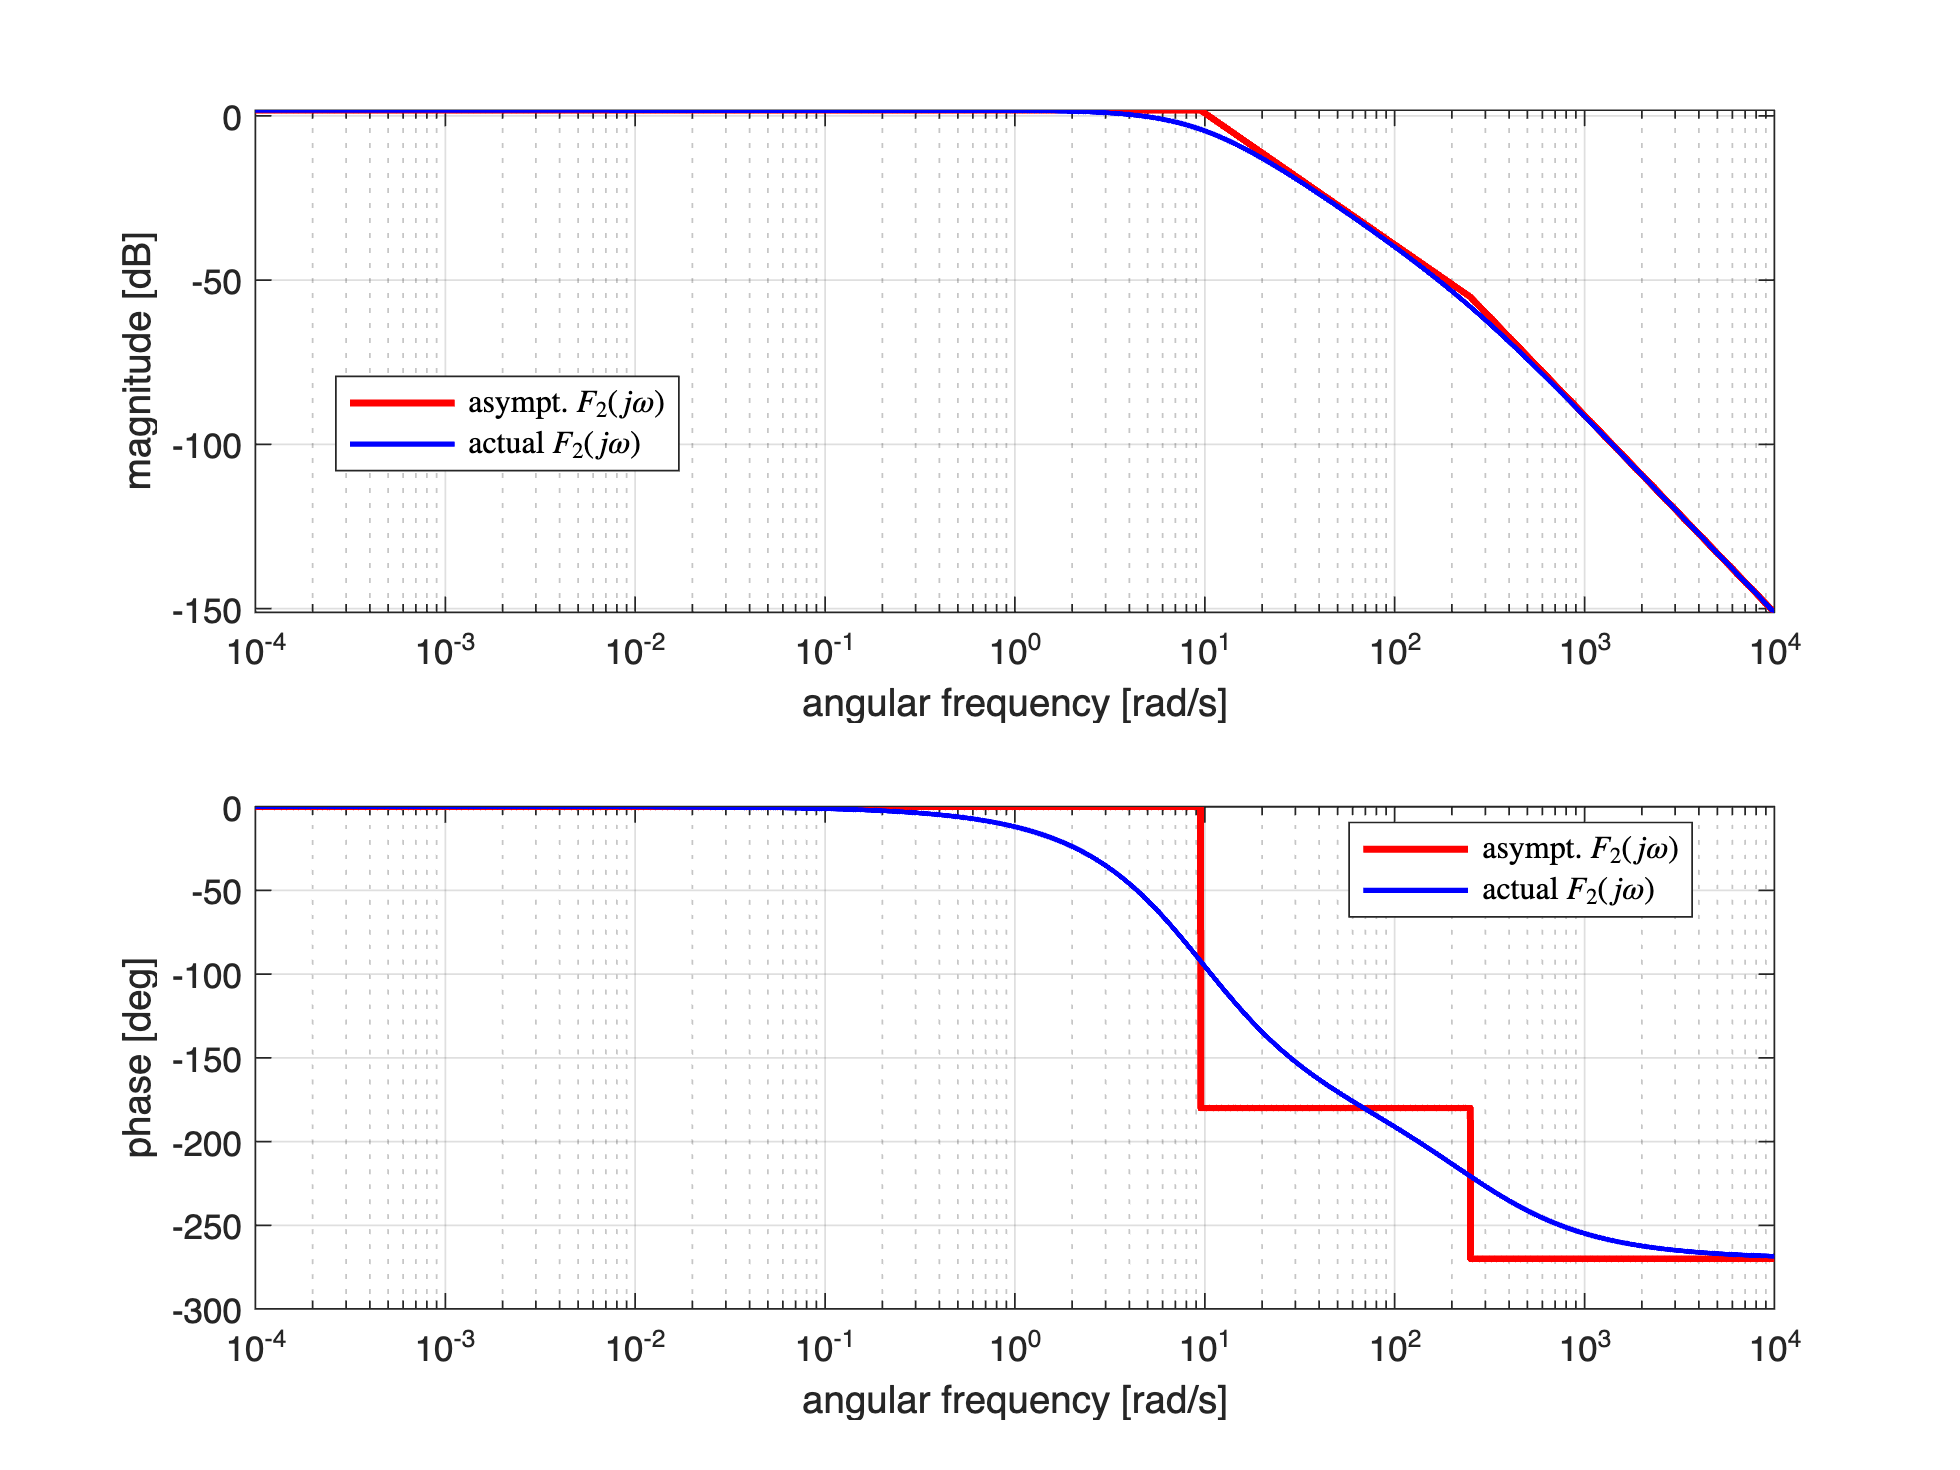

hf = figure('Units','centimeters','Position',[0.01, 0.01, 24, 28]);

omVALS = logspace(-4, +4, 1e4); % 10000 values from 1e-4 up to 1e+4

[ha1, ha2] = drawBodediagrams(F4s, omVALS);
legend(ha1, 'asympt. $F_2(j \omega)$', 'actual $F_2(j \omega)$', ...
        'Interpreter', 'latex', 'location', 'best')
legend(ha2, 'asympt. $F_2(j \omega)$', 'actual $F_2(j \omega)$', ...
        'Interpreter', 'latex', 'location', 'best')

Have we already meet these requirements?

Have a look to the gain and pahse margin of $L_2(s)$

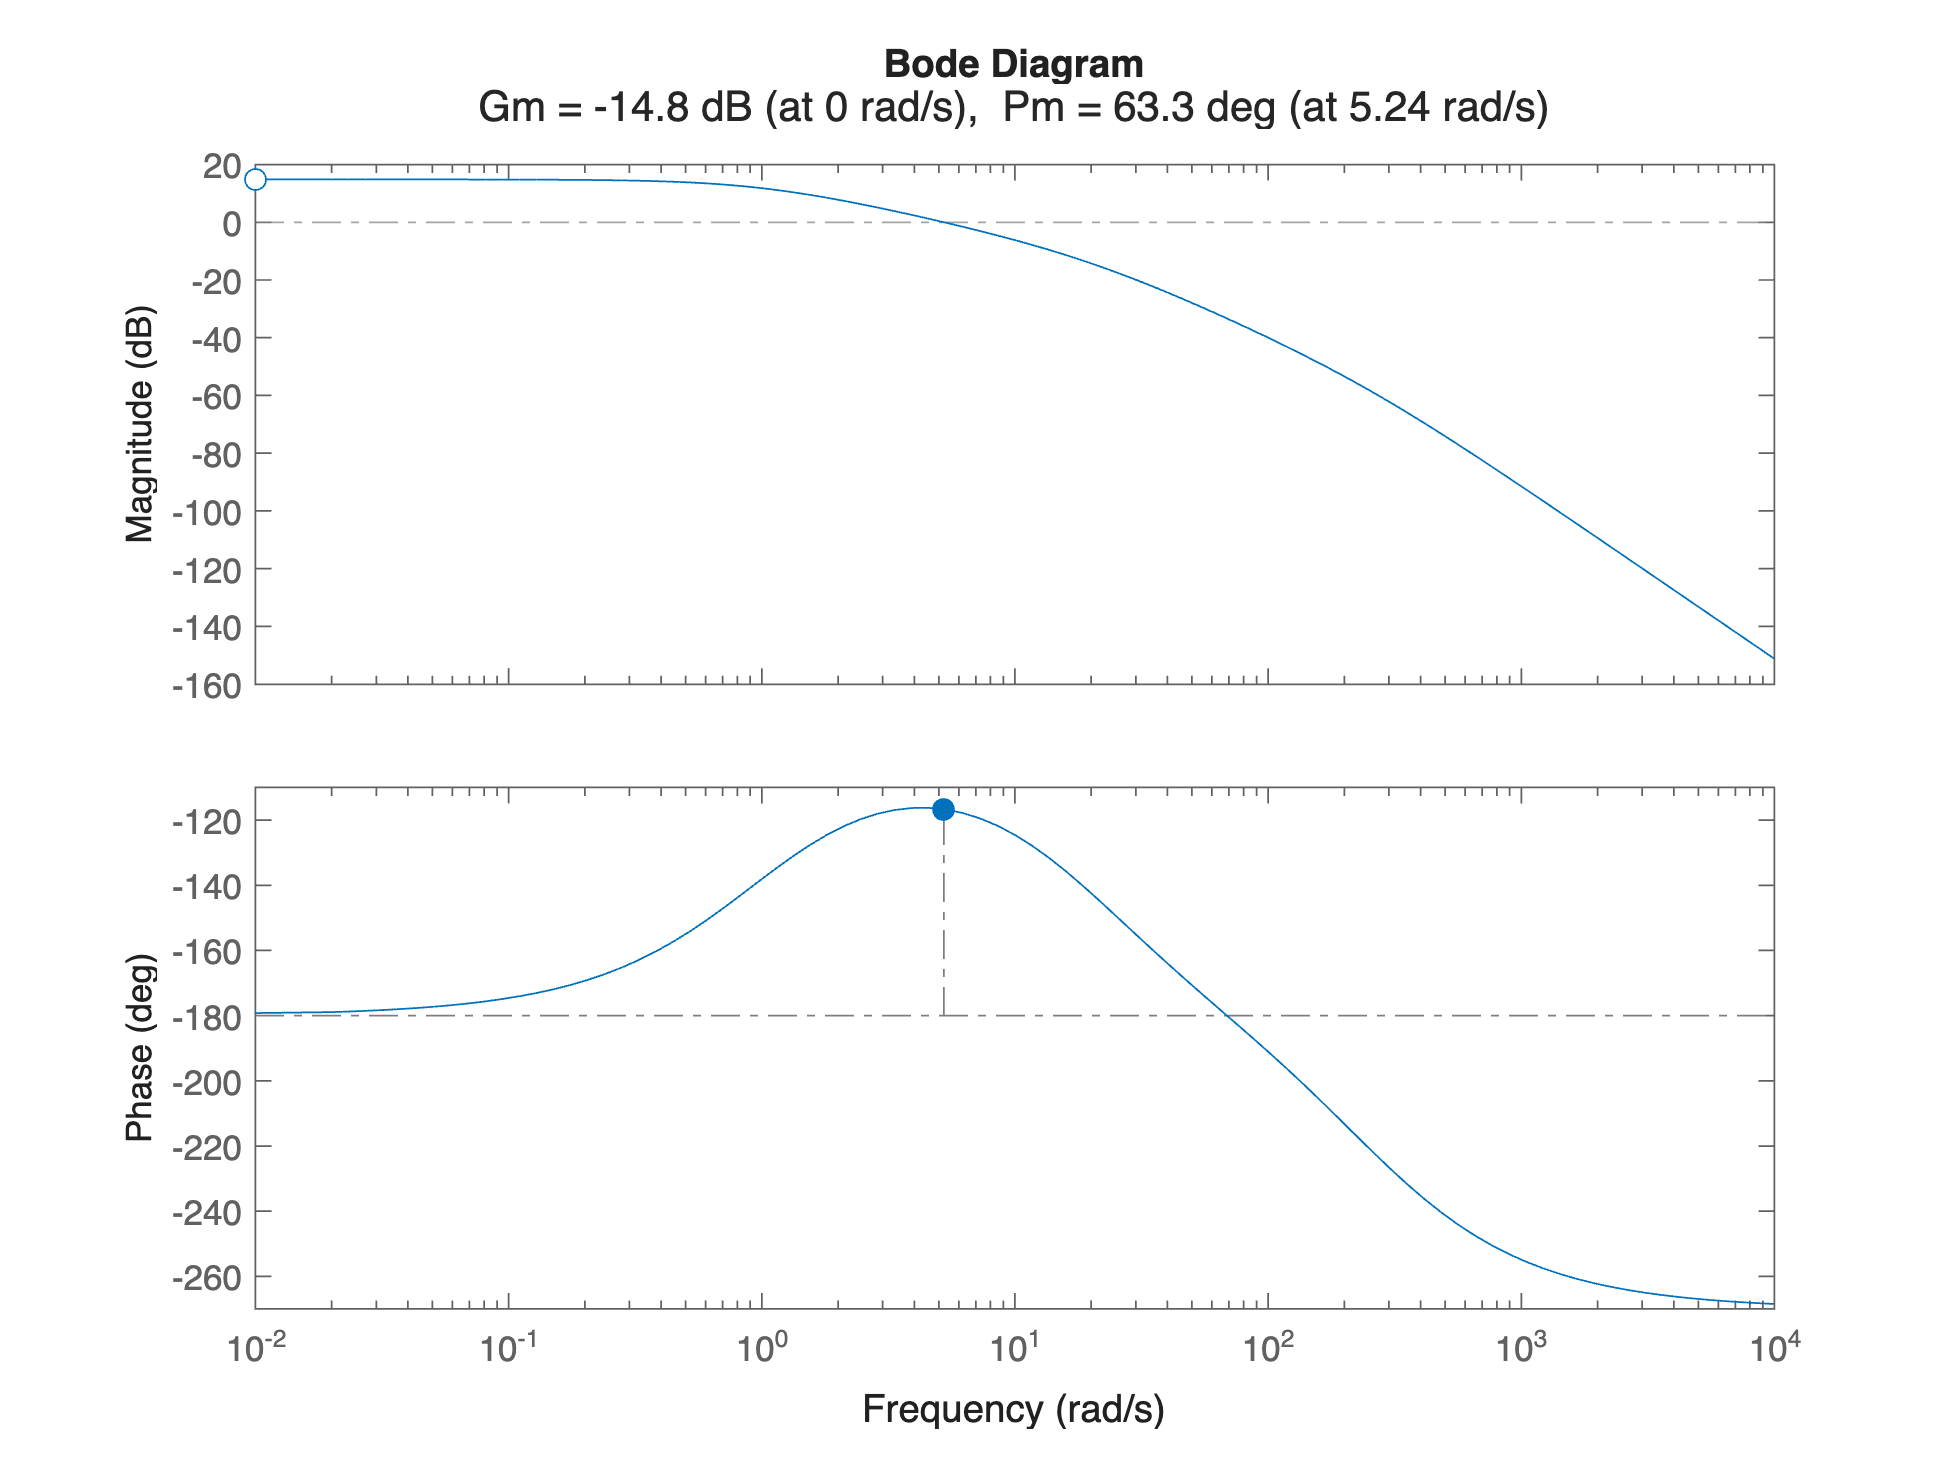

L2s = barMu*L4s;
figure; margin(L2s)

Thus, we don't need any additional outer controller $C_1(s)$. The design is done.

controlSystemDesigner(Gs, C2s)

The session data corresponding to the `controlSystemDesigner` session are available in the MAT file named `ControlSystemDesignerSession3POLES.MAT .`